filename = "more_data.csv"

filename = "more_data.csv"

data = csvread(filename);

acc = data(:, 1:3); % Accelerometer readings
gyro = data(:, 4:6);% Gyroscope readings
mag = data(:, 7:end); %Magnetometer readings

acc_mean = mean(acc).'

acc_mean =     0.0277
    0.7364
    9.9544


gyro_mean = mean(gyro).'

gyro_mean =    -0.5607
   -0.0342
   -0.3706


mag_mean = mean(mag).'

mag_mean =  -129.6265
  141.2333
  -90.4087


% Compute bias
expected_acc = [0; 0; 9.82];
bias_acc = acc_mean - expected_acc

bias_acc =     0.0277
    0.7364
    0.1344


bias_gyro = gyro_mean

bias_gyro =    -0.5607
   -0.0342
   -0.3706


% Correct sensor readings
acc_corr = acc.' - bias_acc;
gyro_corr = gyro.' - bias_gyro;


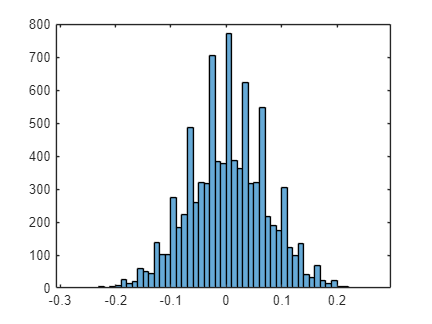

%Checking distribution of sensor values
%histogram(acc_corr(3,:))
histogram(gyro_corr(3,:))

%Fourier transform test
Fs = 1000; 
acc_Y = fft(acc_corr);
L = size(acc_corr, 2)

L = 8889

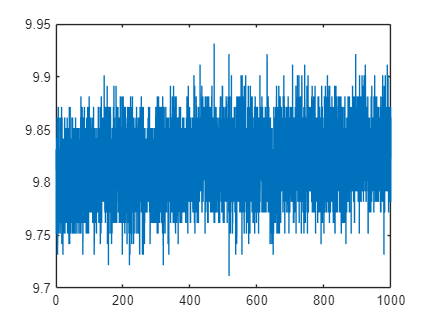

plot(Fs/L*(0:L-1),abs(acc_Y(1,:)))

%Compute covariance of sensors
N = size(data, 1);
cov_acc = ((acc.' - acc_mean) * (acc.' - acc_mean).')/(N-1)

cov_acc = 1.0e-03 *

    0.2831    0.0004   -0.0075
    0.0004    0.3034   -0.0001
   -0.0075   -0.0001    0.2125


cov_gyro = ((gyro.' - gyro_mean) * (gyro.' - gyro_mean).')/(N-1)

cov_gyro =     0.0052    0.0001    0.0000
    0.0001    0.0063   -0.0001
    0.0000   -0.0001    0.0050


cov_mag = ((mag.' - mag_mean) * (mag.' - mag_mean).')/(N-1)

cov_mag =    24.0189    0.0892    0.6901
    0.0892   23.9350   -0.0057
    0.6901   -0.0057   24.4843


sample_rate = 50; %50 hz logging
total_sample_time = N/sample_rate; % total time sampled
dt = 1/sample_rate;
t = 0:dt:total_sample_time-dt

t =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


% NED navigation frame config (x - y - z rotation order).

ax = acc_corr(1,:);
ay = acc_corr(2,:);
az = acc_corr(3,:);

mx = mag(:, 1).';
my = mag(:, 2).';
mz = mag(:, 3).';


pitch = atan2(-ax, sqrt(ay.^2 + az.^2 ))

pitch =     0.0001    0.0011   -0.0020    0.0011    0.0011    0.0001   -0.0009   -0.0020   -0.0030   -0.0009    0.0011   -0.0020    0.0011    0.0001    0.0031   -0.0020   -0.0009   -0.0020    0.0042   -0.0020   -0.0009   -0.0030    0.0001   -0.0020    0.0011   -0.0020   -0.0009   -0.0020   -0.0020   -0.0009    0.0001   -0.0009   -0.0020    0.0001    0.0011    0.0001    0.0001    0.0001   -0.0009   -0.0009    0.0001    0.0001    0.0001    0.0011   -0.0020   -0.0020   -0.0020   -0.0030   -0.0009   -0.0020


roll = atan2(ay, az)

roll =    -0.0118   -0.0097   -0.0118   -0.0097   -0.0108   -0.0108   -0.0108   -0.0098   -0.0097   -0.0097   -0.0098   -0.0108   -0.0108   -0.0077   -0.0098   -0.0108   -0.0108   -0.0087   -0.0077   -0.0128   -0.0108   -0.0067   -0.0118   -0.0118   -0.0077   -0.0118   -0.0128   -0.0087   -0.0118   -0.0138   -0.0077   -0.0098   -0.0108   -0.0097   -0.0087   -0.0097   -0.0118   -0.0108   -0.0098   -0.0098   -0.0118   -0.0128   -0.0098   -0.0087   -0.0087   -0.0108   -0.0118   -0.0087   -0.0118   -0.0118


yaw = -atan2(my .* cos(roll) - mz .* sin(roll), mx .*cos(pitch) + my .* sin(pitch) .* sin(roll) + mz.*sin(pitch).*cos(roll))

yaw =    -1.7375   -1.7331   -1.7308   -1.7331   -1.7142   -1.7191   -1.7501   -1.7404   -1.7560   -1.7668   -1.7497   -1.7822   -1.7331   -1.7568   -1.7359   -1.7540   -1.7122   -1.7530   -1.7336   -1.7266   -1.7312   -1.7463   -1.7281   -1.7486   -1.7548   -1.7545   -1.7190   -1.7277   -1.7328   -1.7311   -1.7311   -1.7215   -1.6989   -1.7543   -1.7331   -1.7184   -1.7468   -1.7118   -1.7149   -1.6806   -1.7184   -1.7283   -1.7408   -1.7553   -1.7265   -1.7296   -1.7143   -1.7497   -1.7090   -1.7234



q = Euler_to_Q(roll, pitch, yaw);

q = [q.w; q.x; q.y; q.z ].';

q0 = [1; 0; 0 ; 0];
for i = 1:N
    q_new = (1/2 * [0;gyro_corr(:, i)] * dt + 1) + q0
    q0 = q_new;
end

q_new =     2.0000
    1.0000
    0.9992
    1.0008


q_new =     3.0000
    2.0001
    1.9992
    2.0015


q_new =     4.0000
    3.0004
    2.9997
    3.0022


q_new =     5.0000
    4.0000
    3.9986
    4.0031


q_new =     6.0000
    4.9993
    4.9980
    5.0037


q_new =     7.0000
    6.0002
    5.9979
    6.0024


q_new =     8.0000
    6.9999
    6.9971
    7.0026


q_new =     9.0000
    8.0001
    7.9975
    8.0028


q_new =    10.0000
    9.0007
    8.9970
    9.0024


q_new =    11.0000
    9.9992
    9.9984
   10.0017


q_new =    12.0000
   10.9992
   10.9980
   11.0014


q_new =    13.0000
   11.9995
   11.9976
   12.0007


q_new =    14.0000
   12.9986
   12.9995
   13.0006


q_new =    15.0000
   13.9988
   14.0010
   14.0006


q_new =    16.0000
   14.9996
   15.0002
   15.0002


q_new =    17.0000
   15.9992
   16.0005
   16.0007


q_new =    18.0000
   16.9995
   17.0009
   17.0003


q_new =    19.0000
   17.9991
   17.9999
   18.0003


q_new =    20.0000
   18.9997
   18.9998
   19.0019


q_new =    21.0000
   19.9987
   20.0011
   20.0022


q_new =    22.0000
   20.9992
   21.0013
   21.0021


q_new =    23.0000
   21.9998
   22.0015
   22.0024


q_new =    24.0000
   23.0004
   23.0026
   23.0034


q_new =    25.0000
   24.0002
   24.0020
   24.0043


q_new =    26.0000
   24.9989
   25.0023
   25.0055


q_new =    27.0000
   25.9994
   26.0023
   26.0066


q_new =    28.0000
   26.9995
   27.0019
   27.0072


q_new =    29.0000
   27.9994
   28.0019
   28.0077


q_new =    30.0000
   28.9986
   29.0009
   29.0078


q_new =    31.0000
   29.9984
   30.0010
   30.0068


q_new =    32.0000
   30.9994
   30.9999
   31.0071


q_new =    33.0000
   31.9997
   32.0013
   32.0077


q_new =    34.0000
   32.9990
   33.0018
   33.0081


q_new =    35.0000
   33.9996
   34.0013
   34.0083


q_new =    36.0000
   34.9999
   35.0016
   35.0070


q_new =    37.0000
   35.9988
   36.0033
   36.0069


q_new =    38.0000
   36.9984
   37.0028
   37.0063


q_new =    39.0000
   37.9981
   38.0039
   38.0055


q_new = 4×1
   40.0000
   38.9978
   39.0034
   39.0052


q_new = 4×1
   41.0000
   39.9970
   40.0036
   40.0046


q_new = 4×1
   42.0000
   40.9979
   41.0037
   41.0058


q_new = 4×1
   43.0000
   41.9985
   42.0013
   42.0043


q_new = 4×1
   44.0000
   42.9996
   43.0018
   43.0051


q_new = 4×1
   45.0000
   43.9977
   44.0011
   44.0054


q_new = 4×1
   46.0000
   44.9980
   45.0020
   45.0061


q_new = 4×1
   47.0000
   45.9980
   46.0017
   46.0068


q_new = 4×1
   48.0000
   46.9988
   47.0014
   47.0054


q_new = 4×1
   49.0000
   47.9978
   48.0020
   48.0050


q_new = 4×1
   50.0000
   48.9978
   49.0026
   49.0043


q_new = 4×1
   51.0000
   49.9979
   50.0024
   50.0040


q_new = 4×1
   52.0000
   50.9984
   51.0027
   51.0045


q_new = 4×1
   53.0000
   51.9997
   52.0042
   52.0035


q_new = 4×1
   54.0000
   53.0003
   53.0056
   53.0031


q_new = 4×1
   55.0000
   53.9991
   54.0070
   54.0027


q_new = 4×1
   56.0000
   54.9997
   55.0071
   55.0025


q_new = 4×1
   57.0000
   55.9995
   56.0079
   56.0025


q_new = 4×1
   58.0000
   56.9998
   57.0070
   57.0021


q_new = 4×1
   59.0000
   57.9996
   58.0066
   58.0029


q_new = 4×1
   60.0000
   59.0007
   59.0068
   59.0020


q_new = 4×1
   61.0000
   59.9991
   60.0061
   60.0007


q_new = 4×1
   62.0000
   60.9991
   61.0053
   60.9999


q_new = 4×1
   63.0000
   61.9995
   62.0067
   62.0000


q_new = 4×1
   64.0000
   62.9997
   63.0076
   62.9997


q_new = 4×1
   65.0000
   63.9998
   64.0074
   64.0002


q_new = 4×1
   66.0000
   65.0001
   65.0069
   64.9989


q_new = 4×1
   67.0000
   66.0012
   66.0073
   65.9984


q_new = 4×1
   68.0000
   67.0012
   67.0061
   66.9970


q_new = 4×1
   69.0000
   67.9996
   68.0048
   67.9979


q_new = 4×1
   70.0000
   68.9999
   69.0043
   68.9973


q_new = 4×1
   71.0000
   69.9998
   70.0059
   69.9967


q_new = 4×1
   72.0000
   70.9997
   71.0059
   70.9961


q_new = 4×1
   73.0000
   72.0000
   72.0054
   71.9968


q_new = 4×1
   74.0000
   73.0008
   73.0066
   72.9958


q_new = 4×1
   75.0000
   74.0004
   74.0064
   73.9952


q_new = 4×1
   76.0000
   74.9999
   75.0068
   74.9937


q_new = 4×1
   77.0000
   76.0005
   76.0072
   75.9941


q_new = 4×1
   78.0000
   77.0004
   77.0075
   76.9937


q_new = 4×1
   79.0000
   77.9998
   78.0076
   77.9929


q_new = 4×1
   80.0000
   78.9989
   79.0073
   78.9932


q_new = 4×1
   81.0000
   79.9992
   80.0075
   79.9924


q_new = 4×1
   82.0000
   80.9984
   81.0076
   80.9921


q_new = 4×1
   83.0000
   81.9985
   82.0085
   81.9914


q_new = 4×1
   84.0000
   82.9992
   83.0082
   82.9906


q_new = 4×1
   85.0000
   83.9994
   84.0084
   83.9898


q_new = 4×1
   86.0000
   84.9997
   85.0072
   84.9899


q_new = 4×1
   87.0000
   86.0001
   86.0060
   85.9887


q_new = 4×1
   88.0000
   87.0003
   87.0059
   86.9884


q_new = 4×1
   89.0000
   87.9995
   88.0066
   87.9874


q_new = 4×1
   90.0000
   89.0001
   89.0081
   88.9886


q_new = 4×1
   91.0000
   89.9997
   90.0072
   89.9892


q_new = 4×1
   92.0000
   90.9996
   91.0062
   90.9897


q_new = 4×1
   93.0000
   91.9985
   92.0067
   91.9914


q_new = 4×1
   94.0000
   92.9975
   93.0063
   92.9919


q_new = 4×1
   95.0000
   93.9970
   94.0069
   93.9913


q_new = 4×1
   96.0000
   94.9966
   95.0070
   94.9897


q_new = 4×1
   97.0000
   95.9976
   96.0073
   95.9897


q_new = 4×1
   98.0000
   96.9972
   97.0078
   96.9908


q_new = 4×1
   99.0000
   97.9966
   98.0083
   97.9911


q_new = 4×1
  100.0000
   98.9965
   99.0084
   98.9917


q_new = 4×1
  101.0000
   99.9969
  100.0076
   99.9919


q_new = 4×1
  102.0000
  100.9975
  101.0092
  100.9915


q_new = 4×1
  103.0000
  101.9969
  102.0100
  101.9924


q_new = 4×1
  104.0000
  102.9966
  103.0097
  102.9927


q_new = 4×1
  105.0000
  103.9958
  104.0099
  103.9925


q_new = 4×1
  106.0000
  104.9951
  105.0117
  104.9913


q_new = 4×1
  107.0000
  105.9954
  106.0111
  105.9913


q_new = 4×1
  108.0000
  106.9959
  107.0108
  106.9918


q_new = 4×1
  109.0000
  107.9960
  108.0121
  107.9920


q_new = 4×1
  110.0000
  108.9959
  109.0135
  108.9932


q_new = 4×1
  111.0000
  109.9948
  110.0136
  109.9918


q_new = 4×1
  112.0000
  110.9945
  111.0128
  110.9920


q_new = 4×1
  113.0000
  111.9938
  112.0127
  111.9932


q_new = 4×1
  114.0000
  112.9933
  113.0120
  112.9926


q_new = 4×1
  115.0000
  113.9936
  114.0112
  113.9928


q_new = 4×1
  116.0000
  114.9946
  115.0107
  114.9928


q_new = 4×1
  117.0000
  115.9943
  116.0108
  115.9938


q_new = 4×1
  118.0000
  116.9952
  117.0102
  116.9938


q_new = 4×1
  119.0000
  117.9949
  118.0101
  117.9927


q_new = 4×1
  120.0000
  118.9950
  119.0097
  118.9920


q_new = 4×1
  121.0000
  119.9959
  120.0110
  119.9915


q_new = 4×1
  122.0000
  120.9961
  121.0104
  120.9911


q_new = 4×1
  123.0000
  121.9966
  122.0093
  121.9908


q_new = 4×1
  124.0000
  122.9954
  123.0090
  122.9912


q_new = 4×1
  125.0000
  123.9953
  124.0084
  123.9924


q_new = 4×1
  126.0000
  124.9956
  125.0086
  124.9927


q_new = 4×1
  127.0000
  125.9955
  126.0077
  125.9928


q_new = 4×1
  128.0000
  126.9961
  127.0082
  126.9930


q_new = 4×1
  129.0000
  127.9957
  128.0091
  127.9933


q_new = 4×1
  130.0000
  128.9955
  129.0096
  128.9928


q_new = 4×1
  131.0000
  129.9956
  130.0089
  129.9936


q_new = 4×1
  132.0000
  130.9961
  131.0094
  130.9934


q_new = 4×1
  133.0000
  131.9969
  132.0094
  131.9932


q_new = 4×1
  134.0000
  132.9977
  133.0096
  132.9928


q_new = 4×1
  135.0000
  133.9977
  134.0098
  133.9922


q_new = 4×1
  136.0000
  134.9985
  135.0091
  134.9921


q_new = 4×1
  137.0000
  135.9970
  136.0093
  135.9924


q_new = 4×1
  138.0000
  136.9980
  137.0090
  136.9923


q_new = 4×1
  139.0000
  137.9972
  138.0096
  137.9926


q_new = 4×1
  140.0000
  138.9949
  139.0095
  138.9924


q_new = 4×1
  141.0000
  139.9948
  140.0087
  139.9933


q_new = 4×1
  142.0000
  140.9950
  141.0085
  140.9933


q_new = 4×1
  143.0000
  141.9957
  142.0093
  141.9926


q_new = 4×1
  144.0000
  142.9959
  143.0096
  142.9920


q_new = 4×1
  145.0000
  143.9964
  144.0098
  143.9926


q_new = 4×1
  146.0000
  144.9969
  145.0101
  144.9926


q_new = 4×1
  147.0000
  145.9958
  146.0106
  145.9918


q_new = 4×1
  148.0000
  146.9947
  147.0118
  146.9934


q_new = 4×1
  149.0000
  147.9936
  148.0118
  147.9942


q_new = 4×1
  150.0000
  148.9942
  149.0116
  148.9943


q_new = 4×1
  151.0000
  149.9943
  150.0121
  149.9954


q_new = 4×1
  152.0000
  150.9948
  151.0124
  150.9954


q_new = 4×1
  153.0000
  151.9953
  152.0138
  151.9956


q_new = 4×1
  154.0000
  152.9938
  153.0143
  152.9956


q_new = 4×1
  155.0000
  153.9937
  154.0133
  153.9968


q_new = 4×1
  156.0000
  154.9938
  155.0137
  154.9978


q_new = 4×1
  157.0000
  155.9932
  156.0142
  155.9983


q_new = 4×1
  158.0000
  156.9931
  157.0138
  156.9993


q_new = 4×1
  159.0000
  157.9943
  158.0150
  158.0001


q_new = 4×1
  160.0000
  158.9955
  159.0156
  158.9997


q_new = 4×1
  161.0000
  159.9953
  160.0166
  159.9991


q_new = 4×1
  162.0000
  160.9952
  161.0154
  161.0002


q_new = 4×1
  163.0000
  161.9951
  162.0151
  161.9997


q_new = 4×1
  164.0000
  162.9960
  163.0157
  162.9997


q_new = 4×1
  165.0000
  163.9963
  164.0165
  164.0006


q_new = 4×1
  166.0000
  164.9965
  165.0173
  165.0008


q_new = 4×1
  167.0000
  165.9977
  166.0172
  166.0004


q_new = 4×1
  168.0000
  166.9977
  167.0173
  167.0005


q_new = 4×1
  169.0000
  167.9980
  168.0182
  168.0008


q_new = 4×1
  170.0000
  168.9986
  169.0177
  169.0018


q_new = 4×1
  171.0000
  169.9989
  170.0167
  170.0023


q_new = 4×1
  172.0000
  170.9999
  171.0177
  171.0029


q_new = 4×1
  173.0000
  171.9983
  172.0177
  172.0030


q_new = 4×1
  174.0000
  172.9984
  173.0182
  173.0032


q_new = 4×1
  175.0000
  173.9973
  174.0175
  174.0029


q_new = 4×1
  176.0000
  174.9974
  175.0184
  175.0018


q_new = 4×1
  177.0000
  175.9974
  176.0178
  175.9993


q_new = 4×1
  178.0000
  176.9969
  177.0173
  176.9984


q_new = 4×1
  179.0000
  177.9972
  178.0178
  177.9976


q_new = 4×1
  180.0000
  178.9960
  179.0180
  178.9982


q_new = 4×1
  181.0000
  179.9961
  180.0169
  179.9977


q_new = 4×1
  182.0000
  180.9956
  181.0158
  180.9982


q_new = 4×1
  183.0000
  181.9950
  182.0152
  181.9986


q_new = 4×1
  184.0000
  182.9956
  183.0147
  182.9979


q_new = 4×1
  185.0000
  183.9957
  184.0147
  183.9986


q_new = 4×1
  186.0000
  184.9952
  185.0147
  184.9992


q_new = 4×1
  187.0000
  185.9959
  186.0134
  185.9991


q_new = 4×1
  188.0000
  186.9959
  187.0136
  186.9988


q_new = 4×1
  189.0000
  187.9958
  188.0134
  187.9978


q_new = 4×1
  190.0000
  188.9955
  189.0120
  188.9972


q_new = 4×1
  191.0000
  189.9958
  190.0116
  189.9979


q_new = 4×1
  192.0000
  190.9954
  191.0112
  190.9971


q_new = 4×1
  193.0000
  191.9959
  192.0112
  191.9963


q_new = 4×1
  194.0000
  192.9958
  193.0111
  192.9960


q_new = 4×1
  195.0000
  193.9969
  194.0102
  193.9952


q_new = 4×1
  196.0000
  194.9974
  195.0097
  194.9952


q_new = 4×1
  197.0000
  195.9982
  196.0095
  195.9963


q_new = 4×1
  198.0000
  196.9980
  197.0088
  196.9959


q_new = 4×1
  199.0000
  197.9983
  198.0088
  197.9963


q_new = 4×1
  200.0000
  198.9984
  199.0084
  198.9959


q_new = 4×1
  201.0000
  199.9988
  200.0089
  199.9964


q_new = 4×1
  202.0000
  200.9998
  201.0081
  200.9963


q_new = 4×1
  203.0000
  202.0004
  202.0077
  201.9965


q_new = 4×1
  204.0000
  203.0004
  203.0082
  202.9974


q_new = 4×1
  205.0000
  204.0018
  204.0071
  203.9980


q_new = 4×1
  206.0000
  205.0013
  205.0061
  204.9981


q_new = 4×1
  207.0000
  206.0021
  206.0054
  205.9991


q_new = 4×1
  208.0000
  207.0008
  207.0053
  206.9989


q_new = 4×1
  209.0000
  208.0014
  208.0065
  207.9988


q_new = 4×1
  210.0000
  209.0023
  209.0060
  208.9991


q_new = 4×1
  211.0000
  210.0023
  210.0053
  209.9990


q_new = 4×1
  212.0000
  211.0015
  211.0043
  210.9991


q_new = 4×1
  213.0000
  212.0018
  212.0051
  211.9986


q_new = 4×1
  214.0000
  213.0018
  213.0043
  212.9978


q_new = 4×1
  215.0000
  214.0016
  214.0053
  213.9972


q_new = 4×1
  216.0000
  215.0018
  215.0055
  214.9971


q_new = 4×1
  217.0000
  216.0019
  216.0044
  215.9965


q_new = 4×1
  218.0000
  217.0015
  217.0056
  216.9966


q_new = 4×1
  219.0000
  218.0026
  218.0052
  217.9961


q_new = 4×1
  220.0000
  219.0022
  219.0055
  218.9963


q_new = 4×1
  221.0000
  220.0034
  220.0062
  219.9972


q_new = 4×1
  222.0000
  221.0023
  221.0051
  220.9968


q_new = 4×1
  223.0000
  222.0038
  222.0055
  221.9965


q_new = 4×1
  224.0000
  223.0050
  223.0050
  222.9961


q_new = 4×1
  225.0000
  224.0042
  224.0049
  223.9963


q_new = 4×1
  226.0000
  225.0033
  225.0063
  224.9961


q_new = 4×1
  227.0000
  226.0030
  226.0080
  225.9966


q_new = 4×1
  228.0000
  227.0024
  227.0076
  226.9965


q_new = 4×1
  229.0000
  228.0029
  228.0081
  227.9965


q_new = 4×1
  230.0000
  229.0018
  229.0096
  228.9953


q_new = 4×1
  231.0000
  230.0026
  230.0092
  229.9958


q_new = 4×1
  232.0000
  231.0030
  231.0107
  230.9957


q_new = 4×1
  233.0000
  232.0035
  232.0113
  231.9949


q_new = 4×1
  234.0000
  233.0051
  233.0127
  232.9956


q_new = 4×1
  235.0000
  234.0045
  234.0127
  233.9949


q_new = 4×1
  236.0000
  235.0026
  235.0120
  234.9945


q_new = 4×1
  237.0000
  236.0018
  236.0118
  235.9946


q_new = 4×1
  238.0000
  237.0011
  237.0119
  236.9931


q_new = 4×1
  239.0000
  238.0007
  238.0126
  237.9948


q_new = 4×1
  240.0000
  239.0015
  239.0128
  238.9951


q_new = 4×1
  241.0000
  240.0013
  240.0111
  239.9941


q_new = 4×1
  242.0000
  241.0009
  241.0101
  240.9940


q_new = 4×1
  243.0000
  242.0013
  242.0093
  241.9936


q_new = 4×1
  244.0000
  243.0013
  243.0101
  242.9935


q_new = 4×1
  245.0000
  244.0001
  244.0090
  243.9928


q_new = 4×1
  246.0000
  245.0006
  245.0089
  244.9931


q_new = 4×1
  247.0000
  246.0003
  246.0089
  245.9911


q_new = 4×1
  248.0000
  246.9994
  247.0079
  246.9913


q_new = 4×1
  249.0000
  247.9986
  248.0081
  247.9910


q_new = 4×1
  250.0000
  248.9975
  249.0088
  248.9918


q_new = 4×1
  251.0000
  249.9978
  250.0096
  249.9914


q_new = 4×1
  252.0000
  250.9971
  251.0098
  250.9911


q_new = 4×1
  253.0000
  251.9964
  252.0094
  251.9919


q_new = 4×1
  254.0000
  252.9964
  253.0093
  252.9916


q_new = 4×1
  255.0000
  253.9964
  254.0076
  253.9915


q_new = 4×1
  256.0000
  254.9956
  255.0086
  254.9918


q_new = 4×1
  257.0000
  255.9959
  256.0091
  255.9928


q_new = 4×1
  258.0000
  256.9960
  257.0108
  256.9919


q_new = 4×1
  259.0000
  257.9963
  258.0101
  257.9910


q_new = 4×1
  260.0000
  258.9974
  259.0117
  258.9917


q_new = 4×1
  261.0000
  259.9968
  260.0124
  259.9916


q_new = 4×1
  262.0000
  260.9968
  261.0117
  260.9903


q_new = 4×1
  263.0000
  261.9980
  262.0118
  261.9903


q_new = 4×1
  264.0000
  262.9977
  263.0121
  262.9885


q_new = 4×1
  265.0000
  263.9977
  264.0113
  263.9882


q_new = 4×1
  266.0000
  264.9975
  265.0115
  264.9877


q_new = 4×1
  267.0000
  265.9975
  266.0115
  265.9883


q_new = 4×1
  268.0000
  266.9972
  267.0109
  266.9886


q_new = 4×1
  269.0000
  267.9975
  268.0101
  267.9899


q_new = 4×1
  270.0000
  268.9994
  269.0082
  268.9898


q_new = 4×1
  271.0000
  269.9990
  270.0067
  269.9885


q_new = 4×1
  272.0000
  270.9981
  271.0057
  270.9885


q_new = 4×1
  273.0000
  271.9975
  272.0050
  271.9878


q_new = 4×1
  274.0000
  272.9983
  273.0056
  272.9865


q_new = 4×1
  275.0000
  273.9978
  274.0054
  273.9865


q_new = 4×1
  276.0000
  274.9975
  275.0051
  274.9864


q_new = 4×1
  277.0000
  275.9969
  276.0043
  275.9879


q_new = 4×1
  278.0000
  276.9976
  277.0033
  276.9873


q_new = 4×1
  279.0000
  277.9987
  278.0048
  277.9884


q_new = 4×1
  280.0000
  278.9984
  279.0044
  278.9879


q_new = 4×1
  281.0000
  279.9981
  280.0040
  279.9871


q_new = 4×1
  282.0000
  280.9971
  281.0032
  280.9869


q_new = 4×1
  283.0000
  281.9973
  282.0042
  281.9875


q_new = 4×1
  284.0000
  282.9979
  283.0029
  282.9878


q_new = 4×1
  285.0000
  283.9981
  284.0018
  283.9864


q_new = 4×1
  286.0000
  284.9981
  285.0016
  284.9852


q_new = 4×1
  287.0000
  285.9974
  286.0014
  285.9853


q_new = 4×1
  288.0000
  286.9983
  287.0013
  286.9846


q_new = 4×1
  289.0000
  287.9979
  288.0013
  287.9836


q_new = 4×1
  290.0000
  288.9984
  289.0018
  288.9835


q_new = 4×1
  291.0000
  289.9979
  290.0021
  289.9842


q_new = 4×1
  292.0000
  290.9985
  291.0021
  290.9836


q_new = 4×1
  293.0000
  291.9981
  292.0023
  291.9840


q_new = 4×1
  294.0000
  292.9988
  293.0015
  292.9841


q_new = 4×1
  295.0000
  293.9982
  294.0009
  293.9834


q_new = 4×1
  296.0000
  294.9975
  294.9996
  294.9842


q_new = 4×1
  297.0000
  295.9960
  295.9989
  295.9842


q_new = 4×1
  298.0000
  296.9970
  296.9987
  296.9849


q_new = 4×1
  299.0000
  297.9958
  297.9963
  297.9842


q_new = 4×1
  300.0000
  298.9961
  298.9963
  298.9845


q_new = 4×1
  301.0000
  299.9951
  299.9955
  299.9846


q_new = 4×1
  302.0000
  300.9951
  300.9963
  300.9849


q_new = 4×1
  303.0000
  301.9955
  301.9955
  301.9847


q_new = 4×1
  304.0000
  302.9958
  302.9957
  302.9856


q_new = 4×1
  305.0000
  303.9965
  303.9953
  303.9859


q_new = 4×1
  306.0000
  304.9958
  304.9959
  304.9850


q_new = 4×1
  307.0000
  305.9957
  305.9953
  305.9843


q_new = 4×1
  308.0000
  306.9972
  306.9959
  306.9835


q_new = 4×1
  309.0000
  307.9985
  307.9961
  307.9834


q_new = 4×1
  310.0000
  308.9983
  308.9956
  308.9837


q_new = 4×1
  311.0000
  309.9980
  309.9969
  309.9848


q_new = 4×1
  312.0000
  310.9988
  310.9955
  310.9841


q_new = 4×1
  313.0000
  311.9994
  311.9955
  311.9851


q_new = 4×1
  314.0000
  312.9986
  312.9955
  312.9854


q_new = 4×1
  315.0000
  313.9982
  313.9965
  313.9859


q_new = 4×1
  316.0000
  314.9974
  314.9967
  314.9862


q_new = 4×1
  317.0000
  315.9980
  315.9967
  315.9854


q_new = 4×1
  318.0000
  316.9986
  316.9979
  316.9854


q_new = 4×1
  319.0000
  317.9982
  317.9985
  317.9860


q_new = 4×1
  320.0000
  318.9968
  318.9984
  318.9861


q_new = 4×1
  321.0000
  319.9976
  319.9990
  319.9854


q_new = 4×1
  322.0000
  320.9979
  321.0000
  320.9855


q_new = 4×1
  323.0000
  321.9980
  321.9989
  321.9855


q_new = 4×1
  324.0000
  322.9978
  322.9991
  322.9855


q_new = 4×1
  325.0000
  323.9973
  323.9990
  323.9862


q_new = 4×1
  326.0000
  324.9976
  324.9981
  324.9860


q_new = 4×1
  327.0000
  325.9977
  325.9985
  325.9862


q_new = 4×1
  328.0000
  326.9977
  326.9982
  326.9861


q_new = 4×1
  329.0000
  327.9977
  327.9977
  327.9861


q_new = 4×1
  330.0000
  328.9979
  328.9979
  328.9852


q_new = 4×1
  331.0000
  329.9975
  329.9983
  329.9848


q_new = 4×1
  332.0000
  330.9981
  330.9976
  330.9851


q_new = 4×1
  333.0000
  331.9969
  331.9972
  331.9851


q_new = 4×1
  334.0000
  332.9963
  332.9987
  332.9846


q_new = 4×1
  335.0000
  333.9964
  333.9984
  333.9846


q_new = 4×1
  336.0000
  334.9980
  334.9979
  334.9844


q_new = 4×1
  337.0000
  335.9989
  335.9979
  335.9854


q_new = 4×1
  338.0000
  336.9974
  336.9982
  336.9866


q_new = 4×1
  339.0000
  337.9964
  337.9976
  337.9865


q_new = 4×1
  340.0000
  338.9961
  338.9984
  338.9867


q_new = 4×1
  341.0000
  339.9962
  339.9973
  339.9874


q_new = 4×1
  342.0000
  340.9959
  340.9965
  340.9862


q_new = 4×1
  343.0000
  341.9961
  341.9977
  341.9866


q_new = 4×1
  344.0000
  342.9952
  342.9986
  342.9854


q_new = 4×1
  345.0000
  343.9941
  343.9990
  343.9847


q_new = 4×1
  346.0000
  344.9947
  344.9995
  344.9848


q_new = 4×1
  347.0000
  345.9931
  346.0002
  345.9841


q_new = 4×1
  348.0000
  346.9931
  346.9999
  346.9834


q_new = 4×1
  349.0000
  347.9930
  347.9982
  347.9828


q_new = 4×1
  350.0000
  348.9925
  348.9991
  348.9829


q_new = 4×1
  351.0000
  349.9911
  350.0002
  349.9840


q_new = 4×1
  352.0000
  350.9895
  350.9996
  350.9846


q_new = 4×1
  353.0000
  351.9893
  351.9994
  351.9856


q_new = 4×1
  354.0000
  352.9891
  353.0001
  352.9852


q_new = 4×1
  355.0000
  353.9891
  354.0022
  353.9857


q_new = 4×1
  356.0000
  354.9890
  355.0028
  354.9844


q_new = 4×1
  357.0000
  355.9886
  356.0023
  355.9857


q_new = 4×1
  358.0000
  356.9886
  357.0026
  356.9853


q_new = 4×1
  359.0000
  357.9876
  358.0022
  357.9857


q_new = 4×1
  360.0000
  358.9870
  359.0023
  358.9871


q_new = 4×1
  361.0000
  359.9884
  360.0013
  359.9873


q_new = 4×1
  362.0000
  360.9887
  361.0008
  360.9864


q_new = 4×1
  363.0000
  361.9893
  361.9997
  361.9864


q_new = 4×1
  364.0000
  362.9891
  363.0002
  362.9869


q_new = 4×1
  365.0000
  363.9896
  364.0022
  363.9876


q_new = 4×1
  366.0000
  364.9905
  365.0027
  364.9895


q_new = 4×1
  367.0000
  365.9902
  366.0030
  365.9892


q_new = 4×1
  368.0000
  366.9909
  367.0025
  366.9887


q_new = 4×1
  369.0000
  367.9916
  368.0025
  367.9892


q_new = 4×1
  370.0000
  368.9913
  369.0032
  368.9893


q_new = 4×1
  371.0000
  369.9906
  370.0041
  369.9893


q_new = 4×1
  372.0000
  370.9915
  371.0037
  370.9891


q_new = 4×1
  373.0000
  371.9907
  372.0038
  371.9893


q_new = 4×1
  374.0000
  372.9902
  373.0040
  372.9895


q_new = 4×1
  375.0000
  373.9906
  374.0041
  373.9903


q_new = 4×1
  376.0000
  374.9908
  375.0037
  374.9910


q_new = 4×1
  377.0000
  375.9896
  376.0036
  375.9915


q_new = 4×1
  378.0000
  376.9899
  377.0026
  376.9917


q_new = 4×1
  379.0000
  377.9888
  378.0033
  377.9911


q_new = 4×1
  380.0000
  378.9888
  379.0022
  378.9912


q_new = 4×1
  381.0000
  379.9906
  380.0036
  379.9910


q_new = 4×1
  382.0000
  380.9909
  381.0038
  380.9921


q_new = 4×1
  383.0000
  381.9919
  382.0029
  381.9917


q_new = 4×1
  384.0000
  382.9919
  383.0024
  382.9905


q_new = 4×1
  385.0000
  383.9920
  384.0012
  383.9904


q_new = 4×1
  386.0000
  384.9917
  385.0021
  384.9908


q_new = 4×1
  387.0000
  385.9901
  386.0015
  385.9916


q_new = 4×1
  388.0000
  386.9900
  387.0022
  386.9912


q_new = 4×1
  389.0000
  387.9912
  388.0027
  387.9906


q_new = 4×1
  390.0000
  388.9907
  389.0024
  388.9909


q_new = 4×1
  391.0000
  389.9907
  390.0032
  389.9920


q_new = 4×1
  392.0000
  390.9909
  391.0012
  390.9920


q_new = 4×1
  393.0000
  391.9908
  392.0002
  391.9930


q_new = 4×1
  394.0000
  392.9921
  393.0006
  392.9933


q_new = 4×1
  395.0000
  393.9924
  394.0019
  393.9935


q_new = 4×1
  396.0000
  394.9925
  395.0015
  394.9936


q_new = 4×1
  397.0000
  395.9925
  396.0022
  395.9937


q_new = 4×1
  398.0000
  396.9925
  397.0015
  396.9937


q_new = 4×1
  399.0000
  397.9913
  398.0001
  397.9935


q_new = 4×1
  400.0000
  398.9922
  398.9997
  398.9936


q_new = 4×1
  401.0000
  399.9922
  400.0008
  399.9933


q_new = 4×1
  402.0000
  400.9923
  401.0009
  400.9938


q_new = 4×1
  403.0000
  401.9921
  402.0004
  401.9928


q_new = 4×1
  404.0000
  402.9915
  403.0000
  402.9926


q_new = 4×1
  405.0000
  403.9907
  404.0000
  403.9932


q_new = 4×1
  406.0000
  404.9910
  404.9999
  404.9938


q_new = 4×1
  407.0000
  405.9906
  405.9995
  405.9930


q_new = 4×1
  408.0000
  406.9905
  407.0000
  406.9942


q_new = 4×1
  409.0000
  407.9910
  407.9990
  407.9924


q_new = 4×1
  410.0000
  408.9899
  408.9982
  408.9926


q_new = 4×1
  411.0000
  409.9896
  409.9967
  409.9924


q_new = 4×1
  412.0000
  410.9885
  410.9972
  410.9909


q_new = 4×1
  413.0000
  411.9888
  411.9979
  411.9906


q_new = 4×1
  414.0000
  412.9875
  412.9972
  412.9901


q_new = 4×1
  415.0000
  413.9877
  413.9963
  413.9895


q_new = 4×1
  416.0000
  414.9876
  414.9958
  414.9892


q_new = 4×1
  417.0000
  415.9881
  415.9954
  415.9902


q_new = 4×1
  418.0000
  416.9887
  416.9959
  416.9892


q_new = 4×1
  419.0000
  417.9890
  417.9952
  417.9895


q_new = 4×1
  420.0000
  418.9889
  418.9957
  418.9898


q_new = 4×1
  421.0000
  419.9889
  419.9949
  419.9895


q_new = 4×1
  422.0000
  420.9876
  420.9962
  420.9889


q_new = 4×1
  423.0000
  421.9886
  421.9964
  421.9881


q_new = 4×1
  424.0000
  422.9884
  422.9956
  422.9884


q_new = 4×1
  425.0000
  423.9871
  423.9957
  423.9882


q_new = 4×1
  426.0000
  424.9870
  424.9949
  424.9878


q_new = 4×1
  427.0000
  425.9870
  425.9946
  425.9871


q_new = 4×1
  428.0000
  426.9870
  426.9955
  426.9877


q_new = 4×1
  429.0000
  427.9882
  427.9951
  427.9886


q_new = 4×1
  430.0000
  428.9886
  428.9966
  428.9893


q_new = 4×1
  431.0000
  429.9869
  429.9963
  429.9882


q_new = 4×1
  432.0000
  430.9859
  430.9965
  430.9888


q_new = 4×1
  433.0000
  431.9867
  431.9954
  431.9873


q_new = 4×1
  434.0000
  432.9871
  432.9955
  432.9869


q_new = 4×1
  435.0000
  433.9882
  433.9947
  433.9866


q_new = 4×1
  436.0000
  434.9883
  434.9963
  434.9866


q_new = 4×1
  437.0000
  435.9878
  435.9968
  435.9862


q_new = 4×1
  438.0000
  436.9874
  436.9965
  436.9860


q_new = 4×1
  439.0000
  437.9870
  437.9958
  437.9859


q_new = 4×1
  440.0000
  438.9879
  438.9953
  438.9848


q_new = 4×1
  441.0000
  439.9869
  439.9951
  439.9860


q_new = 4×1
  442.0000
  440.9872
  440.9955
  440.9861


q_new = 4×1
  443.0000
  441.9880
  441.9957
  441.9850


q_new = 4×1
  444.0000
  442.9883
  442.9969
  442.9845


q_new = 4×1
  445.0000
  443.9872
  443.9967
  443.9847


q_new = 4×1
  446.0000
  444.9863
  444.9965
  444.9858


q_new = 4×1
  447.0000
  445.9856
  445.9968
  445.9857


q_new = 4×1
  448.0000
  446.9865
  446.9961
  446.9878


q_new = 4×1
  449.0000
  447.9863
  447.9946
  447.9879


q_new = 4×1
  450.0000
  448.9845
  448.9948
  448.9879


q_new = 4×1
  451.0000
  449.9848
  449.9951
  449.9884


q_new = 4×1
  452.0000
  450.9861
  450.9946
  450.9883


q_new = 4×1
  453.0000
  451.9856
  451.9947
  451.9870


q_new = 4×1
  454.0000
  452.9848
  452.9952
  452.9861


q_new = 4×1
  455.0000
  453.9847
  453.9952
  453.9874


q_new = 4×1
  456.0000
  454.9849
  454.9938
  454.9873


q_new = 4×1
  457.0000
  455.9838
  455.9924
  455.9852


q_new = 4×1
  458.0000
  456.9847
  456.9915
  456.9866


q_new = 4×1
  459.0000
  457.9846
  457.9930
  457.9877


q_new = 4×1
  460.0000
  458.9844
  458.9937
  458.9867


q_new = 4×1
  461.0000
  459.9840
  459.9959
  459.9877


q_new = 4×1
  462.0000
  460.9838
  460.9962
  460.9883


q_new = 4×1
  463.0000
  461.9839
  461.9975
  461.9891


q_new = 4×1
  464.0000
  462.9839
  462.9975
  462.9881


q_new = 4×1
  465.0000
  463.9839
  463.9961
  463.9874


q_new = 4×1
  466.0000
  464.9829
  464.9950
  464.9877


q_new = 4×1
  467.0000
  465.9838
  465.9944
  465.9876


q_new = 4×1
  468.0000
  466.9848
  466.9949
  466.9869


q_new = 4×1
  469.0000
  467.9840
  467.9945
  467.9872


q_new = 4×1
  470.0000
  468.9842
  468.9948
  468.9882


q_new = 4×1
  471.0000
  469.9857
  469.9955
  469.9884


q_new = 4×1
  472.0000
  470.9849
  470.9950
  470.9877


q_new = 4×1
  473.0000
  471.9851
  471.9944
  471.9888


q_new = 4×1
  474.0000
  472.9852
  472.9937
  472.9885


q_new = 4×1
  475.0000
  473.9855
  473.9952
  473.9887


q_new = 4×1
  476.0000
  474.9854
  474.9956
  474.9879


q_new = 4×1
  477.0000
  475.9851
  475.9951
  475.9877


q_new = 4×1
  478.0000
  476.9864
  476.9955
  476.9886


q_new = 4×1
  479.0000
  477.9864
  477.9947
  477.9882


q_new = 4×1
  480.0000
  478.9853
  478.9944
  478.9875


q_new = 4×1
  481.0000
  479.9861
  479.9936
  479.9875


q_new = 4×1
  482.0000
  480.9861
  480.9941
  480.9880


q_new = 4×1
  483.0000
  481.9859
  481.9954
  481.9890


q_new = 4×1
  484.0000
  482.9860
  482.9965
  482.9893


q_new = 4×1
  485.0000
  483.9858
  483.9964
  483.9902


q_new = 4×1
  486.0000
  484.9859
  484.9976
  484.9914


q_new = 4×1
  487.0000
  485.9848
  485.9965
  485.9909


q_new = 4×1
  488.0000
  486.9843
  486.9972
  486.9895


q_new = 4×1
  489.0000
  487.9840
  487.9977
  487.9892


q_new = 4×1
  490.0000
  488.9855
  488.9976
  488.9889


q_new = 4×1
  491.0000
  489.9857
  489.9983
  489.9893


q_new = 4×1
  492.0000
  490.9856
  490.9987
  490.9893


q_new = 4×1
  493.0000
  491.9843
  491.9995
  491.9890


q_new = 4×1
  494.0000
  492.9838
  492.9991
  492.9891


q_new = 4×1
  495.0000
  493.9837
  493.9976
  493.9905


q_new = 4×1
  496.0000
  494.9837
  494.9972
  494.9901


q_new = 4×1
  497.0000
  495.9837
  495.9965
  495.9904


q_new = 4×1
  498.0000
  496.9831
  496.9951
  496.9892


q_new = 4×1
  499.0000
  497.9819
  497.9956
  497.9897


q_new = 4×1
  500.0000
  498.9823
  498.9949
  498.9888


q_new = 4×1
  501.0000
  499.9822
  499.9963
  499.9893


q_new = 4×1
  502.0000
  500.9829
  500.9963
  500.9902


q_new = 4×1
  503.0000
  501.9835
  501.9948
  501.9905


q_new = 4×1
  504.0000
  502.9838
  502.9949
  502.9911


q_new = 4×1
  505.0000
  503.9827
  503.9962
  503.9921


q_new = 4×1
  506.0000
  504.9834
  504.9951
  504.9924


q_new = 4×1
  507.0000
  505.9827
  505.9943
  505.9929


q_new = 4×1
  508.0000
  506.9827
  506.9949
  506.9916


q_new = 4×1
  509.0000
  507.9823
  507.9951
  507.9909


q_new = 4×1
  510.0000
  508.9818
  508.9951
  508.9901


q_new = 4×1
  511.0000
  509.9821
  509.9946
  509.9898


q_new = 4×1
  512.0000
  510.9819
  510.9956
  510.9893


q_new = 4×1
  513.0000
  511.9832
  511.9963
  511.9899


q_new = 4×1
  514.0000
  512.9829
  512.9962
  512.9892


q_new = 4×1
  515.0000
  513.9832
  513.9957
  513.9888


q_new = 4×1
  516.0000
  514.9841
  514.9956
  514.9883


q_new = 4×1
  517.0000
  515.9830
  515.9959
  515.9889


q_new = 4×1
  518.0000
  516.9829
  516.9944
  516.9895


q_new = 4×1
  519.0000
  517.9827
  517.9940
  517.9882


q_new = 4×1
  520.0000
  518.9835
  518.9928
  518.9879


q_new = 4×1
  521.0000
  519.9841
  519.9913
  519.9885


q_new = 4×1
  522.0000
  520.9841
  520.9903
  520.9879


q_new = 4×1
  523.0000
  521.9847
  521.9902
  521.9895


q_new = 4×1
  524.0000
  522.9855
  522.9890
  522.9892


q_new = 4×1
  525.0000
  523.9855
  523.9890
  523.9890


q_new = 4×1
  526.0000
  524.9860
  524.9895
  524.9892


q_new = 4×1
  527.0000
  525.9860
  525.9890
  525.9902


q_new = 4×1
  528.0000
  526.9868
  526.9897
  526.9897


q_new = 4×1
  529.0000
  527.9874
  527.9894
  527.9913


q_new = 4×1
  530.0000
  528.9870
  528.9897
  528.9917


q_new = 4×1
  531.0000
  529.9870
  529.9908
  529.9932


q_new = 4×1
  532.0000
  530.9866
  530.9905
  530.9918


q_new = 4×1
  533.0000
  531.9874
  531.9915
  531.9915


q_new = 4×1
  534.0000
  532.9891
  532.9908
  532.9912


q_new = 4×1
  535.0000
  533.9900
  533.9889
  533.9915


q_new = 4×1
  536.0000
  534.9906
  534.9889
  534.9910


q_new = 4×1
  537.0000
  535.9903
  535.9898
  535.9919


q_new = 4×1
  538.0000
  536.9896
  536.9906
  536.9911


q_new = 4×1
  539.0000
  537.9901
  537.9899
  537.9911


q_new = 4×1
  540.0000
  538.9894
  538.9897
  538.9900


q_new = 4×1
  541.0000
  539.9882
  539.9892
  539.9907


q_new = 4×1
  542.0000
  540.9881
  540.9895
  540.9918


q_new = 4×1
  543.0000
  541.9882
  541.9903
  541.9914


q_new = 4×1
  544.0000
  542.9886
  542.9897
  542.9915


q_new = 4×1
  545.0000
  543.9896
  543.9892
  543.9920


q_new = 4×1
  546.0000
  544.9886
  544.9888
  544.9922


q_new = 4×1
  547.0000
  545.9878
  545.9883
  545.9928


q_new = 4×1
  548.0000
  546.9881
  546.9875
  546.9924


q_new = 4×1
  549.0000
  547.9877
  547.9866
  547.9916


q_new = 4×1
  550.0000
  548.9869
  548.9871
  548.9909


q_new = 4×1
  551.0000
  549.9873
  549.9873
  549.9908


q_new = 4×1
  552.0000
  550.9873
  550.9878
  550.9904


q_new = 4×1
  553.0000
  551.9879
  551.9875
  551.9904


q_new = 4×1
  554.0000
  552.9882
  552.9870
  552.9904


q_new = 4×1
  555.0000
  553.9879
  553.9864
  553.9897


q_new = 4×1
  556.0000
  554.9890
  554.9857
  554.9903


q_new = 4×1
  557.0000
  555.9896
  555.9852
  555.9904


q_new = 4×1
  558.0000
  556.9896
  556.9856
  556.9917


q_new = 4×1
  559.0000
  557.9882
  557.9855
  557.9922


q_new = 4×1
  560.0000
  558.9888
  558.9860
  558.9914


q_new = 4×1
  561.0000
  559.9884
  559.9870
  559.9901


q_new = 4×1
  562.0000
  560.9890
  560.9869
  560.9907


q_new = 4×1
  563.0000
  561.9895
  561.9865
  561.9912


q_new = 4×1
  564.0000
  562.9901
  562.9856
  562.9914


q_new = 4×1
  565.0000
  563.9907
  563.9862
  563.9911


q_new = 4×1
  566.0000
  564.9899
  564.9878
  564.9902


q_new = 4×1
  567.0000
  565.9896
  565.9876
  565.9888


q_new = 4×1
  568.0000
  566.9896
  566.9873
  566.9887


q_new = 4×1
  569.0000
  567.9891
  567.9880
  567.9881


q_new = 4×1
  570.0000
  568.9894
  568.9886
  568.9885


q_new = 4×1
  571.0000
  569.9890
  569.9875
  569.9885


q_new = 4×1
  572.0000
  570.9890
  570.9878
  570.9885


q_new = 4×1
  573.0000
  571.9890
  571.9873
  571.9884


q_new = 4×1
  574.0000
  572.9895
  572.9865
  572.9892


q_new = 4×1
  575.0000
  573.9896
  573.9872
  573.9896


q_new = 4×1
  576.0000
  574.9892
  574.9864
  574.9909


q_new = 4×1
  577.0000
  575.9895
  575.9875
  575.9910


q_new = 4×1
  578.0000
  576.9887
  576.9872
  576.9915


q_new = 4×1
  579.0000
  577.9890
  577.9876
  577.9920


q_new = 4×1
  580.0000
  578.9887
  578.9872
  578.9913


q_new = 4×1
  581.0000
  579.9893
  579.9868
  579.9915


q_new = 4×1
  582.0000
  580.9897
  580.9873
  580.9913


q_new = 4×1
  583.0000
  581.9897
  581.9876
  581.9902


q_new = 4×1
  584.0000
  582.9896
  582.9873
  582.9895


q_new = 4×1
  585.0000
  583.9892
  583.9853
  583.9892


q_new = 4×1
  586.0000
  584.9898
  584.9849
  584.9905


q_new = 4×1
  587.0000
  585.9901
  585.9844
  585.9906


q_new = 4×1
  588.0000
  586.9909
  586.9830
  586.9894


q_new = 4×1
  589.0000
  587.9909
  587.9821
  587.9898


q_new = 4×1
  590.0000
  588.9908
  588.9823
  588.9898


q_new = 4×1
  591.0000
  589.9924
  589.9816
  589.9897


q_new = 4×1
  592.0000
  590.9920
  590.9820
  590.9888


q_new = 4×1
  593.0000
  591.9921
  591.9810
  591.9878


q_new = 4×1
  594.0000
  592.9921
  592.9810
  592.9877


q_new = 4×1
  595.0000
  593.9932
  593.9820
  593.9876


q_new = 4×1
  596.0000
  594.9935
  594.9831
  594.9882


q_new = 4×1
  597.0000
  595.9935
  595.9832
  595.9889


q_new = 4×1
  598.0000
  596.9935
  596.9845
  596.9883


q_new = 4×1
  599.0000
  597.9933
  597.9844
  597.9881


q_new = 4×1
  600.0000
  598.9922
  598.9862
  598.9875


q_new = 4×1
  601.0000
  599.9910
  599.9857
  599.9865


q_new = 4×1
  602.0000
  600.9913
  600.9867
  600.9853


q_new = 4×1
  603.0000
  601.9908
  601.9867
  601.9852


q_new = 4×1
  604.0000
  602.9920
  602.9860
  602.9871


q_new = 4×1
  605.0000
  603.9926
  603.9874
  603.9883


q_new = 4×1
  606.0000
  604.9928
  604.9875
  604.9876


q_new = 4×1
  607.0000
  605.9925
  605.9863
  605.9865


q_new = 4×1
  608.0000
  606.9928
  606.9866
  606.9861


q_new = 4×1
  609.0000
  607.9924
  607.9867
  607.9865


q_new = 4×1
  610.0000
  608.9926
  608.9863
  608.9861


q_new = 4×1
  611.0000
  609.9938
  609.9847
  609.9874


q_new = 4×1
  612.0000
  610.9940
  610.9843
  610.9864


q_new = 4×1
  613.0000
  611.9937
  611.9855
  611.9865


q_new = 4×1
  614.0000
  612.9938
  612.9855
  612.9868


q_new = 4×1
  615.0000
  613.9938
  613.9855
  613.9873


q_new = 4×1
  616.0000
  614.9945
  614.9844
  614.9871


q_new = 4×1
  617.0000
  615.9943
  615.9844
  615.9880


q_new = 4×1
  618.0000
  616.9940
  616.9846
  616.9894


q_new = 4×1
  619.0000
  617.9948
  617.9850
  617.9890


q_new = 4×1
  620.0000
  618.9953
  618.9854
  618.9887


q_new = 4×1
  621.0000
  619.9956
  619.9846
  619.9895


q_new = 4×1
  622.0000
  620.9952
  620.9850
  620.9884


q_new = 4×1
  623.0000
  621.9995
  621.9887
  621.9893


q_new = 4×1
  624.0000
  622.9962
  622.9909
  622.9890


q_new = 4×1
  625.0000
  623.9983
  623.9920
  623.9892


q_new = 4×1
  626.0000
  624.9992
  624.9909
  624.9879


q_new = 4×1
  627.0000
  626.0001
  625.9899
  625.9881


q_new = 4×1
  628.0000
  627.0004
  626.9902
  626.9886


q_new = 4×1
  629.0000
  627.9994
  627.9889
  627.9890


q_new = 4×1
  630.0000
  628.9996
  628.9885
  628.9893


q_new = 4×1
  631.0000
  630.0005
  629.9883
  629.9899


q_new = 4×1
  632.0000
  631.0006
  630.9879
  630.9903


q_new = 4×1
  633.0000
  631.9993
  631.9877
  631.9919


q_new = 4×1
  634.0000
  632.9997
  632.9876
  632.9927


q_new = 4×1
  635.0000
  633.9982
  633.9883
  633.9924


q_new = 4×1
  636.0000
  634.9988
  634.9884
  634.9923


q_new = 4×1
  637.0000
  635.9993
  635.9881
  635.9916


q_new = 4×1
  638.0000
  636.9999
  636.9868
  636.9908


q_new = 4×1
  639.0000
  637.9987
  637.9858
  637.9917


q_new = 4×1
  640.0000
  639.0000
  638.9850
  638.9909


q_new = 4×1
  641.0000
  639.9995
  639.9845
  639.9922


q_new = 4×1
  642.0000
  640.9981
  640.9842
  640.9917


q_new = 4×1
  643.0000
  641.9981
  641.9845
  641.9917


q_new = 4×1
  644.0000
  642.9973
  642.9843
  642.9918


q_new = 4×1
  645.0000
  643.9979
  643.9841
  643.9929


q_new = 4×1
  646.0000
  644.9965
  644.9842
  644.9938


q_new = 4×1
  647.0000
  645.9967
  645.9848
  645.9950


q_new = 4×1
  648.0000
  646.9961
  646.9853
  646.9952


q_new = 4×1
  649.0000
  647.9971
  647.9857
  647.9955


q_new = 4×1
  650.0000
  648.9969
  648.9854
  648.9961


q_new = 4×1
  651.0000
  649.9974
  649.9832
  649.9963


q_new = 4×1
  652.0000
  650.9969
  650.9821
  650.9962


q_new = 4×1
  653.0000
  651.9960
  651.9831
  651.9957


q_new = 4×1
  654.0000
  652.9963
  652.9820
  652.9953


q_new = 4×1
  655.0000
  653.9955
  653.9816
  653.9947


q_new = 4×1
  656.0000
  654.9942
  654.9818
  654.9957


q_new = 4×1
  657.0000
  655.9951
  655.9817
  655.9953


q_new = 4×1
  658.0000
  656.9955
  656.9813
  656.9959


q_new = 4×1
  659.0000
  657.9965
  657.9805
  657.9953


q_new = 4×1
  660.0000
  658.9959
  658.9803
  658.9948


q_new = 4×1
  661.0000
  659.9960
  659.9809
  659.9943


q_new = 4×1
  662.0000
  660.9960
  660.9806
  660.9942


q_new = 4×1
  663.0000
  661.9967
  661.9809
  661.9948


q_new = 4×1
  664.0000
  662.9970
  662.9811
  662.9964


q_new = 4×1
  665.0000
  663.9977
  663.9801
  663.9966


q_new = 4×1
  666.0000
  664.9972
  664.9803
  664.9975


q_new = 4×1
  667.0000
  665.9974
  665.9795
  665.9977


q_new = 4×1
  668.0000
  666.9977
  666.9795
  666.9977


q_new = 4×1
  669.0000
  667.9960
  667.9794
  667.9974


q_new = 4×1
  670.0000
  668.9949
  668.9777
  668.9960


q_new = 4×1
  671.0000
  669.9948
  669.9782
  669.9961


q_new = 4×1
  672.0000
  670.9943
  670.9768
  670.9972


q_new = 4×1
  673.0000
  671.9957
  671.9769
  671.9964


q_new = 4×1
  674.0000
  672.9952
  672.9774
  672.9959


q_new = 4×1
  675.0000
  673.9958
  673.9789
  673.9958


q_new = 4×1
  676.0000
  674.9961
  674.9775
  674.9954


q_new = 4×1
  677.0000
  675.9960
  675.9763
  675.9965


q_new = 4×1
  678.0000
  676.9963
  676.9765
  676.9970


q_new = 4×1
  679.0000
  677.9964
  677.9767
  677.9972


q_new = 4×1
  680.0000
  678.9964
  678.9778
  678.9967


q_new = 4×1
  681.0000
  679.9949
  679.9779
  679.9968


q_new = 4×1
  682.0000
  680.9952
  680.9769
  680.9965


q_new = 4×1
  683.0000
  681.9958
  681.9782
  681.9968


q_new = 4×1
  684.0000
  682.9948
  682.9803
  682.9961


q_new = 4×1
  685.0000
  683.9952
  683.9808
  683.9950


q_new = 4×1
  686.0000
  684.9939
  684.9814
  684.9953


q_new = 4×1
  687.0000
  685.9937
  685.9813
  685.9959


q_new = 4×1
  688.0000
  686.9947
  686.9824
  686.9961


q_new = 4×1
  689.0000
  687.9943
  687.9824
  687.9957


q_new = 4×1
  690.0000
  688.9950
  688.9821
  688.9957


q_new = 4×1
  691.0000
  689.9943
  689.9827
  689.9957


q_new = 4×1
  692.0000
  690.9938
  690.9842
  690.9949


q_new = 4×1
  693.0000
  691.9935
  691.9837
  691.9952


q_new = 4×1
  694.0000
  692.9937
  692.9832
  692.9953


q_new = 4×1
  695.0000
  693.9934
  693.9815
  693.9949


q_new = 4×1
  696.0000
  694.9919
  694.9813
  694.9943


q_new = 4×1
  697.0000
  695.9909
  695.9807
  695.9942


q_new = 4×1
  698.0000
  696.9902
  696.9803
  696.9945


q_new = 4×1
  699.0000
  697.9899
  697.9810
  697.9946


q_new = 4×1
  700.0000
  698.9892
  698.9819
  698.9945


q_new = 4×1
  701.0000
  699.9901
  699.9822
  699.9950


q_new = 4×1
  702.0000
  700.9898
  700.9820
  700.9951


q_new = 4×1
  703.0000
  701.9892
  701.9819
  701.9952


q_new = 4×1
  704.0000
  702.9882
  702.9809
  702.9962


q_new = 4×1
  705.0000
  703.9882
  703.9809
  703.9958


q_new = 4×1
  706.0000
  704.9872
  704.9821
  704.9951


q_new = 4×1
  707.0000
  705.9868
  705.9825
  705.9947


q_new = 4×1
  708.0000
  706.9861
  706.9822
  706.9939


q_new = 4×1
  709.0000
  707.9862
  707.9822
  707.9930


q_new = 4×1
  710.0000
  708.9869
  708.9830
  708.9924


q_new = 4×1
  711.0000
  709.9874
  709.9841
  709.9916


q_new = 4×1
  712.0000
  710.9872
  710.9842
  710.9917


q_new = 4×1
  713.0000
  711.9878
  711.9838
  711.9914


q_new = 4×1
  714.0000
  712.9881
  712.9829
  712.9896


q_new = 4×1
  715.0000
  713.9881
  713.9819
  713.9902


q_new = 4×1
  716.0000
  714.9886
  714.9801
  714.9896


q_new = 4×1
  717.0000
  715.9889
  715.9795
  715.9886


q_new = 4×1
  718.0000
  716.9897
  716.9790
  716.9880


q_new = 4×1
  719.0000
  717.9895
  717.9787
  717.9874


q_new = 4×1
  720.0000
  718.9875
  718.9785
  718.9874


q_new = 4×1
  721.0000
  719.9873
  719.9799
  719.9871


q_new = 4×1
  722.0000
  720.9879
  720.9808
  720.9875


q_new = 4×1
  723.0000
  721.9875
  721.9803
  721.9870


q_new = 4×1
  724.0000
  722.9878
  722.9798
  722.9873


q_new = 4×1
  725.0000
  723.9881
  723.9815
  723.9873


q_new = 4×1
  726.0000
  724.9871
  724.9811
  724.9883


q_new = 4×1
  727.0000
  725.9880
  725.9814
  725.9892


q_new = 4×1
  728.0000
  726.9874
  726.9797
  726.9887


q_new = 4×1
  729.0000
  727.9879
  727.9818
  727.9895


q_new = 4×1
  730.0000
  728.9882
  728.9807
  728.9868


q_new = 4×1
  731.0000
  729.9892
  729.9819
  729.9878


q_new = 4×1
  732.0000
  730.9895
  730.9818
  730.9888


q_new = 4×1
  733.0000
  731.9887
  731.9810
  731.9883


q_new = 4×1
  734.0000
  732.9883
  732.9816
  732.9884


q_new = 4×1
  735.0000
  733.9889
  733.9816
  733.9877


q_new = 4×1
  736.0000
  734.9892
  734.9831
  734.9874


q_new = 4×1
  737.0000
  735.9887
  735.9817
  735.9890


q_new = 4×1
  738.0000
  736.9887
  736.9821
  736.9895


q_new = 4×1
  739.0000
  737.9880
  737.9826
  737.9878


q_new = 4×1
  740.0000
  738.9885
  738.9847
  738.9880


q_new = 4×1
  741.0000
  739.9874
  739.9853
  739.9874


q_new = 4×1
  742.0000
  740.9875
  740.9857
  740.9864


q_new = 4×1
  743.0000
  741.9883
  741.9853
  741.9872


q_new = 4×1
  744.0000
  742.9872
  742.9853
  742.9865


q_new = 4×1
  745.0000
  743.9876
  743.9843
  743.9856


q_new = 4×1
  746.0000
  744.9879
  744.9850
  744.9866


q_new = 4×1
  747.0000
  745.9878
  745.9859
  745.9863


q_new = 4×1
  748.0000
  746.9877
  746.9870
  746.9857


q_new = 4×1
  749.0000
  747.9887
  747.9872
  747.9843


q_new = 4×1
  750.0000
  748.9889
  748.9868
  748.9861


q_new = 4×1
  751.0000
  749.9881
  749.9867
  749.9853


q_new = 4×1
  752.0000
  750.9881
  750.9870
  750.9851


q_new = 4×1
  753.0000
  751.9886
  751.9890
  751.9853


q_new = 4×1
  754.0000
  752.9889
  752.9889
  752.9840


q_new = 4×1
  755.0000
  753.9893
  753.9903
  753.9837


q_new = 4×1
  756.0000
  754.9887
  754.9907
  754.9838


q_new = 4×1
  757.0000
  755.9889
  755.9921
  755.9843


q_new = 4×1
  758.0000
  756.9882
  756.9911
  756.9847


q_new = 4×1
  759.0000
  757.9884
  757.9894
  757.9847


q_new = 4×1
  760.0000
  758.9887
  758.9902
  758.9859


q_new = 4×1
  761.0000
  759.9889
  759.9913
  759.9859


q_new = 4×1
  762.0000
  760.9883
  760.9915
  760.9859


q_new = 4×1
  763.0000
  761.9885
  761.9904
  761.9864


q_new = 4×1
  764.0000
  762.9878
  762.9908
  762.9867


q_new = 4×1
  765.0000
  763.9873
  763.9912
  763.9868


q_new = 4×1
  766.0000
  764.9880
  764.9901
  764.9877


q_new = 4×1
  767.0000
  765.9884
  765.9896
  765.9887


q_new = 4×1
  768.0000
  766.9880
  766.9893
  766.9887


q_new = 4×1
  769.0000
  767.9877
  767.9902
  767.9891


q_new = 4×1
  770.0000
  768.9879
  768.9898
  768.9900


q_new = 4×1
  771.0000
  769.9879
  769.9887
  769.9890


q_new = 4×1
  772.0000
  770.9875
  770.9876
  770.9894


q_new = 4×1
  773.0000
  771.9871
  771.9875
  771.9887


q_new = 4×1
  774.0000
  772.9863
  772.9883
  772.9876


q_new = 4×1
  775.0000
  773.9857
  773.9889
  773.9890


q_new = 4×1
  776.0000
  774.9850
  774.9910
  774.9897


q_new = 4×1
  777.0000
  775.9856
  775.9915
  775.9906


q_new = 4×1
  778.0000
  776.9847
  776.9927
  776.9895


q_new = 4×1
  779.0000
  777.9840
  777.9926
  777.9881


q_new = 4×1
  780.0000
  778.9854
  778.9912
  778.9879


q_new = 4×1
  781.0000
  779.9857
  779.9916
  779.9886


q_new = 4×1
  782.0000
  780.9869
  780.9906
  780.9878


q_new = 4×1
  783.0000
  781.9871
  781.9916
  781.9883


q_new = 4×1
  784.0000
  782.9861
  782.9913
  782.9885


q_new = 4×1
  785.0000
  783.9858
  783.9912
  783.9882


q_new = 4×1
  786.0000
  784.9842
  784.9921
  784.9870


q_new = 4×1
  787.0000
  785.9846
  785.9911
  785.9872


q_new = 4×1
  788.0000
  786.9854
  786.9905
  786.9872


q_new = 4×1
  789.0000
  787.9853
  787.9895
  787.9884


q_new = 4×1
  790.0000
  788.9849
  788.9893
  788.9874


q_new = 4×1
  791.0000
  789.9852
  789.9883
  789.9882


q_new = 4×1
  792.0000
  790.9850
  790.9879
  790.9887


q_new = 4×1
  793.0000
  791.9846
  791.9862
  791.9888


q_new = 4×1
  794.0000
  792.9846
  792.9853
  792.9894


q_new = 4×1
  795.0000
  793.9844
  793.9857
  793.9895


q_new = 4×1
  796.0000
  794.9840
  794.9855
  794.9895


q_new = 4×1
  797.0000
  795.9853
  795.9861
  795.9898


q_new = 4×1
  798.0000
  796.9849
  796.9858
  796.9892


q_new = 4×1
  799.0000
  797.9839
  797.9860
  797.9904


q_new = 4×1
  800.0000
  798.9844
  798.9838
  798.9907


q_new = 4×1
  801.0000
  799.9844
  799.9827
  799.9891


q_new = 4×1
  802.0000
  800.9837
  800.9819
  800.9875


q_new = 4×1
  803.0000
  801.9840
  801.9811
  801.9865


q_new = 4×1
  804.0000
  802.9836
  802.9813
  802.9877


q_new = 4×1
  805.0000
  803.9837
  803.9808
  803.9880


q_new = 4×1
  806.0000
  804.9846
  804.9819
  804.9877


q_new = 4×1
  807.0000
  805.9848
  805.9820
  805.9877


q_new = 4×1
  808.0000
  806.9849
  806.9828
  806.9883


q_new = 4×1
  809.0000
  807.9847
  807.9821
  807.9885


q_new = 4×1
  810.0000
  808.9852
  808.9828
  808.9891


q_new = 4×1
  811.0000
  809.9859
  809.9833
  809.9883


q_new = 4×1
  812.0000
  810.9862
  810.9847
  810.9887


q_new = 4×1
  813.0000
  811.9883
  811.9840
  811.9893


q_new = 4×1
  814.0000
  812.9902
  812.9846
  812.9911


q_new = 4×1
  815.0000
  813.9902
  813.9853
  813.9914


q_new = 4×1
  816.0000
  814.9911
  814.9849
  814.9916


q_new = 4×1
  817.0000
  815.9916
  815.9851
  815.9908


q_new = 4×1
  818.0000
  816.9922
  816.9859
  816.9910


q_new = 4×1
  819.0000
  817.9921
  817.9865
  817.9902


q_new = 4×1
  820.0000
  818.9933
  818.9868
  818.9905


q_new = 4×1
  821.0000
  819.9933
  819.9853
  819.9912


q_new = 4×1
  822.0000
  820.9924
  820.9862
  820.9911


q_new = 4×1
  823.0000
  821.9926
  821.9857
  821.9916


q_new = 4×1
  824.0000
  822.9932
  822.9871
  822.9922


q_new = 4×1
  825.0000
  823.9914
  823.9867
  823.9906


q_new = 4×1
  826.0000
  824.9915
  824.9862
  824.9909


q_new = 4×1
  827.0000
  825.9920
  825.9857
  825.9907


q_new = 4×1
  828.0000
  826.9923
  826.9852
  826.9906


q_new = 4×1
  829.0000
  827.9921
  827.9857
  827.9913


q_new = 4×1
  830.0000
  828.9911
  828.9857
  828.9917


q_new = 4×1
  831.0000
  829.9908
  829.9852
  829.9915


q_new = 4×1
  832.0000
  830.9904
  830.9859
  830.9918


q_new = 4×1
  833.0000
  831.9910
  831.9860
  831.9910


q_new = 4×1
  834.0000
  832.9913
  832.9859
  832.9914


q_new = 4×1
  835.0000
  833.9900
  833.9861
  833.9909


q_new = 4×1
  836.0000
  834.9887
  834.9874
  834.9899


q_new = 4×1
  837.0000
  835.9878
  835.9889
  835.9896


q_new = 4×1
  838.0000
  836.9868
  836.9912
  836.9903


q_new = 4×1
  839.0000
  837.9864
  837.9924
  837.9910


q_new = 4×1
  840.0000
  838.9867
  838.9923
  838.9905


q_new = 4×1
  841.0000
  839.9849
  839.9913
  839.9903


q_new = 4×1
  842.0000
  840.9851
  840.9906
  840.9901


q_new = 4×1
  843.0000
  841.9859
  841.9904
  841.9912


q_new = 4×1
  844.0000
  842.9859
  842.9904
  842.9916


q_new = 4×1
  845.0000
  843.9861
  843.9906
  843.9924


q_new = 4×1
  846.0000
  844.9861
  844.9897
  844.9921


q_new = 4×1
  847.0000
  845.9866
  845.9906
  845.9925


q_new = 4×1
  848.0000
  846.9849
  846.9900
  846.9929


q_new = 4×1
  849.0000
  847.9846
  847.9893
  847.9925


q_new = 4×1
  850.0000
  848.9852
  848.9893
  848.9923


q_new = 4×1
  851.0000
  849.9856
  849.9895
  849.9933


q_new = 4×1
  852.0000
  850.9858
  850.9891
  850.9928


q_new = 4×1
  853.0000
  851.9854
  851.9902
  851.9925


q_new = 4×1
  854.0000
  852.9851
  852.9903
  852.9938


q_new = 4×1
  855.0000
  853.9860
  853.9903
  853.9943


q_new = 4×1
  856.0000
  854.9843
  854.9899
  854.9953


q_new = 4×1
  857.0000
  855.9843
  855.9903
  855.9957


q_new = 4×1
  858.0000
  856.9833
  856.9908
  856.9967


q_new = 4×1
  859.0000
  857.9845
  857.9911
  857.9964


q_new = 4×1
  860.0000
  858.9845
  858.9895
  858.9961


q_new = 4×1
  861.0000
  859.9844
  859.9885
  859.9970


q_new = 4×1
  862.0000
  860.9852
  860.9874
  860.9977


q_new = 4×1
  863.0000
  861.9841
  861.9885
  861.9979


q_new = 4×1
  864.0000
  862.9835
  862.9884
  862.9978


q_new = 4×1
  865.0000
  863.9836
  863.9883
  863.9963


q_new = 4×1
  866.0000
  864.9842
  864.9876
  864.9960


q_new = 4×1
  867.0000
  865.9846
  865.9883
  865.9958


q_new = 4×1
  868.0000
  866.9855
  866.9892
  866.9954


q_new = 4×1
  869.0000
  867.9845
  867.9897
  867.9957


q_new = 4×1
  870.0000
  868.9858
  868.9893
  868.9959


q_new = 4×1
  871.0000
  869.9867
  869.9890
  869.9965


q_new = 4×1
  872.0000
  870.9856
  870.9894
  870.9952


q_new = 4×1
  873.0000
  871.9864
  871.9902
  871.9952


q_new = 4×1
  874.0000
  872.9858
  872.9887
  872.9952


q_new = 4×1
  875.0000
  873.9851
  873.9887
  873.9953


q_new = 4×1
  876.0000
  874.9860
  874.9888
  874.9962


q_new = 4×1
  877.0000
  875.9863
  875.9885
  875.9961


q_new = 4×1
  878.0000
  876.9868
  876.9882
  876.9959


q_new = 4×1
  879.0000
  877.9858
  877.9877
  877.9951


q_new = 4×1
  880.0000
  878.9848
  878.9879
  878.9954


q_new = 4×1
  881.0000
  879.9857
  879.9879
  879.9963


q_new = 4×1
  882.0000
  880.9852
  880.9878
  880.9968


q_new = 4×1
  883.0000
  881.9846
  881.9872
  881.9977


q_new = 4×1
  884.0000
  882.9851
  882.9870
  882.9963


q_new = 4×1
  885.0000
  883.9850
  883.9871
  883.9963


q_new = 4×1
  886.0000
  884.9849
  884.9852
  884.9966


q_new = 4×1
  887.0000
  885.9846
  885.9860
  885.9969


q_new = 4×1
  888.0000
  886.9841
  886.9852
  886.9959


q_new = 4×1
  889.0000
  887.9849
  887.9853
  887.9955


q_new = 4×1
  890.0000
  888.9852
  888.9852
  888.9954


q_new = 4×1
  891.0000
  889.9863
  889.9859
  889.9943


q_new = 4×1
  892.0000
  890.9857
  890.9846
  890.9945


q_new = 4×1
  893.0000
  891.9868
  891.9851
  891.9944


q_new = 4×1
  894.0000
  892.9868
  892.9835
  892.9944


q_new = 4×1
  895.0000
  893.9868
  893.9835
  893.9932


q_new = 4×1
  896.0000
  894.9864
  894.9835
  894.9936


q_new = 4×1
  897.0000
  895.9877
  895.9825
  895.9940


q_new = 4×1
  898.0000
  896.9883
  896.9827
  896.9947


q_new = 4×1
  899.0000
  897.9896
  897.9818
  897.9950


q_new = 4×1
  900.0000
  898.9882
  898.9817
  898.9956


q_new = 4×1
  901.0000
  899.9888
  899.9815
  899.9960


q_new = 4×1
  902.0000
  900.9876
  900.9810
  900.9966


q_new = 4×1
  903.0000
  901.9865
  901.9815
  901.9969


q_new = 4×1
  904.0000
  902.9867
  902.9815
  902.9971


q_new = 4×1
  905.0000
  903.9870
  903.9826
  903.9974


q_new = 4×1
  906.0000
  904.9866
  904.9821
  904.9977


q_new = 4×1
  907.0000
  905.9880
  905.9827
  905.9982


q_new = 4×1
  908.0000
  906.9879
  906.9823
  906.9979


q_new = 4×1
  909.0000
  907.9888
  907.9822
  907.9968


q_new = 4×1
  910.0000
  908.9898
  908.9813
  908.9964


q_new = 4×1
  911.0000
  909.9924
  909.9797
  909.9955


q_new = 4×1
  912.0000
  910.9939
  910.9777
  910.9947


q_new = 4×1
  913.0000
  911.9952
  911.9790
  911.9942


q_new = 4×1
  914.0000
  912.9955
  912.9786
  912.9947


q_new = 4×1
  915.0000
  913.9979
  913.9778
  913.9954


q_new = 4×1
  916.0000
  914.9983
  914.9768
  914.9963


q_new = 4×1
  917.0000
  915.9976
  915.9783
  915.9952


q_new = 4×1
  918.0000
  916.9964
  916.9786
  916.9949


q_new = 4×1
  919.0000
  917.9973
  917.9776
  917.9955


q_new = 4×1
  920.0000
  918.9969
  918.9778
  918.9942


q_new = 4×1
  921.0000
  919.9980
  919.9786
  919.9939


q_new = 4×1
  922.0000
  920.9997
  920.9788
  920.9930


q_new = 4×1
  923.0000
  921.9997
  921.9779
  921.9938


q_new = 4×1
  924.0000
  922.9984
  922.9784
  922.9938


q_new = 4×1
  925.0000
  924.0156
  923.9828
  923.9945


q_new = 4×1
  926.0000
  925.0093
  924.9811
  924.9940


q_new = 4×1
  927.0000
  926.0154
  925.9829
  925.9934


q_new = 4×1
  928.0000
  927.0112
  926.9837
  926.9930


q_new = 4×1
  929.0000
  928.0173
  927.9844
  927.9921


q_new = 4×1
  930.0000
  929.0144
  928.9841
  928.9910


q_new = 4×1
  931.0000
  930.0149
  929.9834
  929.9911


q_new = 4×1
  932.0000
  931.0147
  930.9824
  930.9917


q_new = 4×1
  933.0000
  932.0143
  931.9827
  931.9919


q_new = 4×1
  934.0000
  933.0125
  932.9814
  932.9925


q_new = 4×1
  935.0000
  934.0141
  933.9814
  933.9926


q_new = 4×1
  936.0000
  935.0141
  934.9807
  934.9935


q_new = 4×1
  937.0000
  936.0141
  935.9794
  935.9935


q_new = 4×1
  938.0000
  937.0149
  936.9772
  936.9931


q_new = 4×1
  939.0000
  938.0153
  937.9769
  937.9940


q_new = 4×1
  940.0000
  939.0143
  938.9764
  938.9929


q_new = 4×1
  941.0000
  940.0145
  939.9770
  939.9931


q_new = 4×1
  942.0000
  941.0141
  940.9775
  940.9934


q_new = 4×1
  943.0000
  942.0159
  941.9783
  941.9944


q_new = 4×1
  944.0000
  943.0159
  942.9783
  942.9945


q_new = 4×1
  945.0000
  944.0161
  943.9775
  943.9948


q_new = 4×1
  946.0000
  945.0159
  944.9765
  944.9945


q_new = 4×1
  947.0000
  946.0152
  945.9765
  945.9942


q_new = 4×1
  948.0000
  947.0160
  946.9763
  946.9947


q_new = 4×1
  949.0000
  948.0172
  947.9761
  947.9952


q_new = 4×1
  950.0000
  949.0178
  948.9753
  948.9953


q_new = 4×1
  951.0000
  950.0174
  949.9750
  949.9950


q_new = 4×1
  952.0000
  951.0180
  950.9739
  950.9950


q_new = 4×1
  953.0000
  952.0199
  951.9735
  951.9951


q_new = 4×1
  954.0000
  953.0209
  952.9740
  952.9962


q_new = 4×1
  955.0000
  954.0209
  953.9756
  953.9953


q_new = 4×1
  956.0000
  955.0207
  954.9748
  954.9954


q_new = 4×1
  957.0000
  956.0203
  955.9748
  955.9963


q_new = 4×1
  958.0000
  957.0197
  956.9748
  956.9970


q_new = 4×1
  959.0000
  958.0189
  957.9756
  957.9965


q_new = 4×1
  960.0000
  959.0199
  958.9745
  958.9964


q_new = 4×1
  961.0000
  960.0192
  959.9750
  959.9966


q_new = 4×1
  962.0000
  961.0189
  960.9752
  960.9953


q_new = 4×1
  963.0000
  962.0198
  961.9762
  961.9948


q_new = 4×1
  964.0000
  963.0187
  962.9777
  962.9954


q_new = 4×1
  965.0000
  964.0191
  963.9775
  963.9953


q_new = 4×1
  966.0000
  965.0193
  964.9773
  964.9950


q_new = 4×1
  967.0000
  966.0204
  965.9768
  965.9944


q_new = 4×1
  968.0000
  967.0212
  966.9751
  966.9943


q_new = 4×1
  969.0000
  968.0223
  967.9732
  967.9943


q_new = 4×1
  970.0000
  969.0226
  968.9718
  968.9936


q_new = 4×1
  971.0000
  970.0215
  969.9707
  969.9932


q_new = 4×1
  972.0000
  971.0215
  970.9703
  970.9933


q_new = 4×1
  973.0000
  972.0209
  971.9705
  971.9938


q_new = 4×1
  974.0000
  973.0219
  972.9711
  972.9944


q_new = 4×1
  975.0000
  974.0218
  973.9707
  973.9944


q_new = 4×1
  976.0000
  975.0227
  974.9708
  974.9949


q_new = 4×1
  977.0000
  976.0227
  975.9715
  975.9949


q_new = 4×1
  978.0000
  977.0233
  976.9719
  976.9959


q_new = 4×1
  979.0000
  978.0222
  977.9715
  977.9966


q_new = 4×1
  980.0000
  979.0220
  978.9718
  978.9960


q_new = 4×1
  981.0000
  980.0218
  979.9719
  979.9950


q_new = 4×1
  982.0000
  981.0222
  980.9727
  980.9949


q_new = 4×1
  983.0000
  982.0214
  981.9725
  981.9958


q_new = 4×1
  984.0000
  983.0214
  982.9722
  982.9963


q_new = 4×1
  985.0000
  984.0209
  983.9722
  983.9959


q_new = 4×1
  986.0000
  985.0208
  984.9732
  984.9972


q_new = 4×1
  987.0000
  986.0204
  985.9711
  985.9974


q_new = 4×1
  988.0000
  987.0202
  986.9713
  986.9960


q_new = 4×1
  989.0000
  988.0194
  987.9700
  987.9975


q_new = 4×1
  990.0000
  989.0196
  988.9704
  988.9974


q_new = 4×1
  991.0000
  990.0205
  989.9718
  989.9986


q_new = 4×1
  992.0000
  991.0212
  990.9723
  990.9975


q_new = 4×1
  993.0000
  992.0224
  991.9699
  991.9977


q_new = 4×1
  994.0000
  993.0215
  992.9701
  992.9977


q_new = 4×1
  995.0000
  994.0215
  993.9701
  993.9967


q_new = 4×1
  996.0000
  995.0207
  994.9701
  994.9966


q_new = 4×1
  997.0000
  996.0193
  995.9697
  995.9969


q_new = 4×1
  998.0000
  997.0179
  996.9707
  996.9958


q_new = 4×1
  999.0000
  998.0175
  997.9710
  997.9967


q_new = 4×1
1.0e+03 *

    1.0000
    0.9990
    0.9990
    0.9990


q_new = 4×1
1.0e+03 *

    1.0010
    1.0000
    1.0000
    1.0000


q_new = 4×1
1.0e+03 *

    1.0020
    1.0010
    1.0010
    1.0010


q_new = 4×1
1.0e+03 *

    1.0030
    1.0020
    1.0020
    1.0020


q_new = 4×1
1.0e+03 *

    1.0040
    1.0030
    1.0030
    1.0030


q_new = 4×1
1.0e+03 *

    1.0050
    1.0040
    1.0040
    1.0040


q_new = 4×1
1.0e+03 *

    1.0060
    1.0050
    1.0050
    1.0050


q_new = 4×1
1.0e+03 *

    1.0070
    1.0060
    1.0060
    1.0060


q_new = 4×1
1.0e+03 *

    1.0080
    1.0070
    1.0070
    1.0070


q_new = 4×1
1.0e+03 *

    1.0090
    1.0080
    1.0080
    1.0080


q_new = 4×1
1.0e+03 *

    1.0100
    1.0090
    1.0090
    1.0090


q_new = 4×1
1.0e+03 *

    1.0110
    1.0100
    1.0100
    1.0100


q_new = 4×1
1.0e+03 *

    1.0120
    1.0110
    1.0110
    1.0110


q_new = 4×1
1.0e+03 *

    1.0130
    1.0120
    1.0120
    1.0120


q_new = 4×1
1.0e+03 *

    1.0140
    1.0130
    1.0130
    1.0130


q_new = 4×1
1.0e+03 *

    1.0150
    1.0140
    1.0140
    1.0140


q_new = 4×1
1.0e+03 *

    1.0160
    1.0150
    1.0150
    1.0150


q_new = 4×1
1.0e+03 *

    1.0170
    1.0160
    1.0160
    1.0160


q_new = 4×1
1.0e+03 *

    1.0180
    1.0170
    1.0170
    1.0170


q_new = 4×1
1.0e+03 *

    1.0190
    1.0180
    1.0180
    1.0180


q_new = 4×1
1.0e+03 *

    1.0200
    1.0190
    1.0190
    1.0190


q_new = 4×1
1.0e+03 *

    1.0210
    1.0200
    1.0200
    1.0200


q_new = 4×1
1.0e+03 *

    1.0220
    1.0210
    1.0210
    1.0210


q_new = 4×1
1.0e+03 *

    1.0230
    1.0220
    1.0220
    1.0220


q_new = 4×1
1.0e+03 *

    1.0240
    1.0230
    1.0230
    1.0230


q_new = 4×1
1.0e+03 *

    1.0250
    1.0240
    1.0240
    1.0240


q_new = 4×1
1.0e+03 *

    1.0260
    1.0250
    1.0250
    1.0250


q_new = 4×1
1.0e+03 *

    1.0270
    1.0260
    1.0260
    1.0260


q_new = 4×1
1.0e+03 *

    1.0280
    1.0270
    1.0270
    1.0270


q_new = 4×1
1.0e+03 *

    1.0290
    1.0280
    1.0280
    1.0280


q_new = 4×1
1.0e+03 *

    1.0300
    1.0290
    1.0290
    1.0290


q_new = 4×1
1.0e+03 *

    1.0310
    1.0300
    1.0300
    1.0300


q_new = 4×1
1.0e+03 *

    1.0320
    1.0310
    1.0310
    1.0310


q_new = 4×1
1.0e+03 *

    1.0330
    1.0320
    1.0320
    1.0320


q_new = 4×1
1.0e+03 *

    1.0340
    1.0330
    1.0330
    1.0330


q_new = 4×1
1.0e+03 *

    1.0350
    1.0340
    1.0340
    1.0340


q_new = 4×1
1.0e+03 *

    1.0360
    1.0350
    1.0350
    1.0350


q_new = 4×1
1.0e+03 *

    1.0370
    1.0360
    1.0360
    1.0360


q_new = 4×1
1.0e+03 *

    1.0380
    1.0370
    1.0370
    1.0370


q_new = 4×1
1.0e+03 *

    1.0390
    1.0380
    1.0380
    1.0380


q_new = 4×1
1.0e+03 *

    1.0400
    1.0390
    1.0390
    1.0390


q_new = 4×1
1.0e+03 *

    1.0410
    1.0400
    1.0400
    1.0400


q_new = 4×1
1.0e+03 *

    1.0420
    1.0410
    1.0410
    1.0410


q_new = 4×1
1.0e+03 *

    1.0430
    1.0420
    1.0420
    1.0420


q_new = 4×1
1.0e+03 *

    1.0440
    1.0430
    1.0430
    1.0430


q_new = 4×1
1.0e+03 *

    1.0450
    1.0440
    1.0440
    1.0440


q_new = 4×1
1.0e+03 *

    1.0460
    1.0450
    1.0450
    1.0450


q_new = 4×1
1.0e+03 *

    1.0470
    1.0460
    1.0460
    1.0460


q_new = 4×1
1.0e+03 *

    1.0480
    1.0470
    1.0470
    1.0470


q_new = 4×1
1.0e+03 *

    1.0490
    1.0480
    1.0480
    1.0480


q_new = 4×1
1.0e+03 *

    1.0500
    1.0490
    1.0490
    1.0490


q_new = 4×1
1.0e+03 *

    1.0510
    1.0500
    1.0500
    1.0500


q_new = 4×1
1.0e+03 *

    1.0520
    1.0510
    1.0510
    1.0510


q_new = 4×1
1.0e+03 *

    1.0530
    1.0520
    1.0520
    1.0520


q_new = 4×1
1.0e+03 *

    1.0540
    1.0530
    1.0530
    1.0530


q_new = 4×1
1.0e+03 *

    1.0550
    1.0540
    1.0540
    1.0540


q_new = 4×1
1.0e+03 *

    1.0560
    1.0550
    1.0550
    1.0550


q_new = 4×1
1.0e+03 *

    1.0570
    1.0560
    1.0560
    1.0560


q_new = 4×1
1.0e+03 *

    1.0580
    1.0570
    1.0570
    1.0570


q_new = 4×1
1.0e+03 *

    1.0590
    1.0580
    1.0580
    1.0580


q_new = 4×1
1.0e+03 *

    1.0600
    1.0590
    1.0590
    1.0590


q_new = 4×1
1.0e+03 *

    1.0610
    1.0600
    1.0600
    1.0600


q_new = 4×1
1.0e+03 *

    1.0620
    1.0610
    1.0610
    1.0610


q_new = 4×1
1.0e+03 *

    1.0630
    1.0620
    1.0620
    1.0620


q_new = 4×1
1.0e+03 *

    1.0640
    1.0630
    1.0630
    1.0630


q_new = 4×1
1.0e+03 *

    1.0650
    1.0640
    1.0640
    1.0640


q_new = 4×1
1.0e+03 *

    1.0660
    1.0650
    1.0650
    1.0650


q_new = 4×1
1.0e+03 *

    1.0670
    1.0660
    1.0660
    1.0660


q_new = 4×1
1.0e+03 *

    1.0680
    1.0670
    1.0670
    1.0670


q_new = 4×1
1.0e+03 *

    1.0690
    1.0680
    1.0680
    1.0680


q_new = 4×1
1.0e+03 *

    1.0700
    1.0690
    1.0690
    1.0690


q_new = 4×1
1.0e+03 *

    1.0710
    1.0700
    1.0700
    1.0700


q_new = 4×1
1.0e+03 *

    1.0720
    1.0710
    1.0710
    1.0710


q_new = 4×1
1.0e+03 *

    1.0730
    1.0720
    1.0720
    1.0720


q_new = 4×1
1.0e+03 *

    1.0740
    1.0730
    1.0730
    1.0730


q_new = 4×1
1.0e+03 *

    1.0750
    1.0740
    1.0740
    1.0740


q_new = 4×1
1.0e+03 *

    1.0760
    1.0750
    1.0750
    1.0750


q_new = 4×1
1.0e+03 *

    1.0770
    1.0760
    1.0760
    1.0760


q_new = 4×1
1.0e+03 *

    1.0780
    1.0770
    1.0770
    1.0770


q_new = 4×1
1.0e+03 *

    1.0790
    1.0780
    1.0780
    1.0780


q_new = 4×1
1.0e+03 *

    1.0800
    1.0790
    1.0790
    1.0790


q_new = 4×1
1.0e+03 *

    1.0810
    1.0800
    1.0800
    1.0800


q_new = 4×1
1.0e+03 *

    1.0820
    1.0810
    1.0810
    1.0810


q_new = 4×1
1.0e+03 *

    1.0830
    1.0820
    1.0820
    1.0820


q_new = 4×1
1.0e+03 *

    1.0840
    1.0830
    1.0830
    1.0830


q_new = 4×1
1.0e+03 *

    1.0850
    1.0840
    1.0840
    1.0840


q_new = 4×1
1.0e+03 *

    1.0860
    1.0850
    1.0850
    1.0850


q_new = 4×1
1.0e+03 *

    1.0870
    1.0860
    1.0860
    1.0860


q_new = 4×1
1.0e+03 *

    1.0880
    1.0870
    1.0870
    1.0870


q_new = 4×1
1.0e+03 *

    1.0890
    1.0880
    1.0880
    1.0880


q_new = 4×1
1.0e+03 *

    1.0900
    1.0890
    1.0890
    1.0890


q_new = 4×1
1.0e+03 *

    1.0910
    1.0900
    1.0900
    1.0900


q_new = 4×1
1.0e+03 *

    1.0920
    1.0910
    1.0910
    1.0910


q_new = 4×1
1.0e+03 *

    1.0930
    1.0920
    1.0920
    1.0920


q_new = 4×1
1.0e+03 *

    1.0940
    1.0930
    1.0930
    1.0930


q_new = 4×1
1.0e+03 *

    1.0950
    1.0940
    1.0940
    1.0940


q_new = 4×1
1.0e+03 *

    1.0960
    1.0950
    1.0950
    1.0950


q_new = 4×1
1.0e+03 *

    1.0970
    1.0960
    1.0960
    1.0960


q_new = 4×1
1.0e+03 *

    1.0980
    1.0970
    1.0970
    1.0970


q_new = 4×1
1.0e+03 *

    1.0990
    1.0980
    1.0980
    1.0980


q_new = 4×1
1.0e+03 *

    1.1000
    1.0990
    1.0990
    1.0990


q_new = 4×1
1.0e+03 *

    1.1010
    1.1000
    1.1000
    1.1000


q_new = 4×1
1.0e+03 *

    1.1020
    1.1010
    1.1010
    1.1010


q_new = 4×1
1.0e+03 *

    1.1030
    1.1020
    1.1020
    1.1020


q_new = 4×1
1.0e+03 *

    1.1040
    1.1030
    1.1030
    1.1030


q_new = 4×1
1.0e+03 *

    1.1050
    1.1040
    1.1040
    1.1040


q_new = 4×1
1.0e+03 *

    1.1060
    1.1050
    1.1050
    1.1050


q_new = 4×1
1.0e+03 *

    1.1070
    1.1060
    1.1060
    1.1060


q_new = 4×1
1.0e+03 *

    1.1080
    1.1070
    1.1070
    1.1070


q_new = 4×1
1.0e+03 *

    1.1090
    1.1080
    1.1080
    1.1080


q_new = 4×1
1.0e+03 *

    1.1100
    1.1090
    1.1090
    1.1090


q_new = 4×1
1.0e+03 *

    1.1110
    1.1100
    1.1100
    1.1100


q_new = 4×1
1.0e+03 *

    1.1120
    1.1110
    1.1110
    1.1110


q_new = 4×1
1.0e+03 *

    1.1130
    1.1120
    1.1120
    1.1120


q_new = 4×1
1.0e+03 *

    1.1140
    1.1130
    1.1130
    1.1130


q_new = 4×1
1.0e+03 *

    1.1150
    1.1140
    1.1140
    1.1140


q_new = 4×1
1.0e+03 *

    1.1160
    1.1150
    1.1150
    1.1150


q_new = 4×1
1.0e+03 *

    1.1170
    1.1160
    1.1160
    1.1160


q_new = 4×1
1.0e+03 *

    1.1180
    1.1170
    1.1170
    1.1170


q_new = 4×1
1.0e+03 *

    1.1190
    1.1180
    1.1180
    1.1180


q_new = 4×1
1.0e+03 *

    1.1200
    1.1190
    1.1190
    1.1190


q_new = 4×1
1.0e+03 *

    1.1210
    1.1200
    1.1200
    1.1200


q_new = 4×1
1.0e+03 *

    1.1220
    1.1210
    1.1210
    1.1210


q_new = 4×1
1.0e+03 *

    1.1230
    1.1220
    1.1220
    1.1220


q_new = 4×1
1.0e+03 *

    1.1240
    1.1230
    1.1230
    1.1230


q_new = 4×1
1.0e+03 *

    1.1250
    1.1240
    1.1240
    1.1240


q_new = 4×1
1.0e+03 *

    1.1260
    1.1250
    1.1250
    1.1250


q_new = 4×1
1.0e+03 *

    1.1270
    1.1260
    1.1260
    1.1260


q_new = 4×1
1.0e+03 *

    1.1280
    1.1270
    1.1270
    1.1270


q_new = 4×1
1.0e+03 *

    1.1290
    1.1280
    1.1280
    1.1280


q_new = 4×1
1.0e+03 *

    1.1300
    1.1290
    1.1290
    1.1290


q_new = 4×1
1.0e+03 *

    1.1310
    1.1300
    1.1300
    1.1300


q_new = 4×1
1.0e+03 *

    1.1320
    1.1310
    1.1310
    1.1310


q_new = 4×1
1.0e+03 *

    1.1330
    1.1320
    1.1320
    1.1320


q_new = 4×1
1.0e+03 *

    1.1340
    1.1330
    1.1330
    1.1330


q_new = 4×1
1.0e+03 *

    1.1350
    1.1340
    1.1340
    1.1340


q_new = 4×1
1.0e+03 *

    1.1360
    1.1350
    1.1350
    1.1350


q_new = 4×1
1.0e+03 *

    1.1370
    1.1360
    1.1360
    1.1360


q_new = 4×1
1.0e+03 *

    1.1380
    1.1370
    1.1370
    1.1370


q_new = 4×1
1.0e+03 *

    1.1390
    1.1380
    1.1380
    1.1380


q_new = 4×1
1.0e+03 *

    1.1400
    1.1390
    1.1390
    1.1390


q_new = 4×1
1.0e+03 *

    1.1410
    1.1400
    1.1400
    1.1400


q_new = 4×1
1.0e+03 *

    1.1420
    1.1410
    1.1410
    1.1410


q_new = 4×1
1.0e+03 *

    1.1430
    1.1420
    1.1420
    1.1420


q_new = 4×1
1.0e+03 *

    1.1440
    1.1430
    1.1430
    1.1430


q_new = 4×1
1.0e+03 *

    1.1450
    1.1440
    1.1440
    1.1440


q_new = 4×1
1.0e+03 *

    1.1460
    1.1450
    1.1450
    1.1450


q_new = 4×1
1.0e+03 *

    1.1470
    1.1460
    1.1460
    1.1460


q_new = 4×1
1.0e+03 *

    1.1480
    1.1470
    1.1470
    1.1470


q_new = 4×1
1.0e+03 *

    1.1490
    1.1480
    1.1480
    1.1480


q_new = 4×1
1.0e+03 *

    1.1500
    1.1490
    1.1490
    1.1490


q_new = 4×1
1.0e+03 *

    1.1510
    1.1500
    1.1500
    1.1500


q_new = 4×1
1.0e+03 *

    1.1520
    1.1510
    1.1510
    1.1510


q_new = 4×1
1.0e+03 *

    1.1530
    1.1520
    1.1520
    1.1520


q_new = 4×1
1.0e+03 *

    1.1540
    1.1530
    1.1530
    1.1530


q_new = 4×1
1.0e+03 *

    1.1550
    1.1540
    1.1540
    1.1540


q_new = 4×1
1.0e+03 *

    1.1560
    1.1550
    1.1550
    1.1550


q_new = 4×1
1.0e+03 *

    1.1570
    1.1560
    1.1560
    1.1560


q_new = 4×1
1.0e+03 *

    1.1580
    1.1570
    1.1570
    1.1570


q_new = 4×1
1.0e+03 *

    1.1590
    1.1580
    1.1580
    1.1580


q_new = 4×1
1.0e+03 *

    1.1600
    1.1590
    1.1590
    1.1590


q_new = 4×1
1.0e+03 *

    1.1610
    1.1600
    1.1600
    1.1600


q_new = 4×1
1.0e+03 *

    1.1620
    1.1610
    1.1610
    1.1610


q_new = 4×1
1.0e+03 *

    1.1630
    1.1620
    1.1620
    1.1620


q_new = 4×1
1.0e+03 *

    1.1640
    1.1630
    1.1630
    1.1630


q_new = 4×1
1.0e+03 *

    1.1650
    1.1640
    1.1640
    1.1640


q_new = 4×1
1.0e+03 *

    1.1660
    1.1650
    1.1650
    1.1650


q_new = 4×1
1.0e+03 *

    1.1670
    1.1660
    1.1660
    1.1660


q_new = 4×1
1.0e+03 *

    1.1680
    1.1670
    1.1670
    1.1670


q_new = 4×1
1.0e+03 *

    1.1690
    1.1680
    1.1680
    1.1680


q_new = 4×1
1.0e+03 *

    1.1700
    1.1690
    1.1690
    1.1690


q_new = 4×1
1.0e+03 *

    1.1710
    1.1700
    1.1700
    1.1700


q_new = 4×1
1.0e+03 *

    1.1720
    1.1710
    1.1710
    1.1710


q_new = 4×1
1.0e+03 *

    1.1730
    1.1720
    1.1720
    1.1720


q_new = 4×1
1.0e+03 *

    1.1740
    1.1730
    1.1730
    1.1730


q_new = 4×1
1.0e+03 *

    1.1750
    1.1740
    1.1740
    1.1740


q_new = 4×1
1.0e+03 *

    1.1760
    1.1750
    1.1750
    1.1750


q_new = 4×1
1.0e+03 *

    1.1770
    1.1760
    1.1760
    1.1760


q_new = 4×1
1.0e+03 *

    1.1780
    1.1770
    1.1770
    1.1770


q_new = 4×1
1.0e+03 *

    1.1790
    1.1780
    1.1780
    1.1780


q_new = 4×1
1.0e+03 *

    1.1800
    1.1790
    1.1790
    1.1790


q_new = 4×1
1.0e+03 *

    1.1810
    1.1800
    1.1800
    1.1800


q_new = 4×1
1.0e+03 *

    1.1820
    1.1810
    1.1810
    1.1810


q_new = 4×1
1.0e+03 *

    1.1830
    1.1820
    1.1820
    1.1820


q_new = 4×1
1.0e+03 *

    1.1840
    1.1830
    1.1830
    1.1830


q_new = 4×1
1.0e+03 *

    1.1850
    1.1840
    1.1840
    1.1840


q_new = 4×1
1.0e+03 *

    1.1860
    1.1850
    1.1850
    1.1850


q_new = 4×1
1.0e+03 *

    1.1870
    1.1860
    1.1860
    1.1860


q_new = 4×1
1.0e+03 *

    1.1880
    1.1870
    1.1870
    1.1870


q_new = 4×1
1.0e+03 *

    1.1890
    1.1880
    1.1880
    1.1880


q_new = 4×1
1.0e+03 *

    1.1900
    1.1890
    1.1890
    1.1890


q_new = 4×1
1.0e+03 *

    1.1910
    1.1900
    1.1900
    1.1900


q_new = 4×1
1.0e+03 *

    1.1920
    1.1910
    1.1910
    1.1910


q_new = 4×1
1.0e+03 *

    1.1930
    1.1920
    1.1920
    1.1920


q_new = 4×1
1.0e+03 *

    1.1940
    1.1930
    1.1930
    1.1930


q_new = 4×1
1.0e+03 *

    1.1950
    1.1940
    1.1940
    1.1940


q_new = 4×1
1.0e+03 *

    1.1960
    1.1950
    1.1950
    1.1950


q_new = 4×1
1.0e+03 *

    1.1970
    1.1960
    1.1960
    1.1960


q_new = 4×1
1.0e+03 *

    1.1980
    1.1970
    1.1970
    1.1970


q_new = 4×1
1.0e+03 *

    1.1990
    1.1980
    1.1980
    1.1980


q_new = 4×1
1.0e+03 *

    1.2000
    1.1990
    1.1990
    1.1990


q_new = 4×1
1.0e+03 *

    1.2010
    1.2000
    1.2000
    1.2000


q_new = 4×1
1.0e+03 *

    1.2020
    1.2010
    1.2010
    1.2010


q_new = 4×1
1.0e+03 *

    1.2030
    1.2020
    1.2020
    1.2020


q_new = 4×1
1.0e+03 *

    1.2040
    1.2030
    1.2030
    1.2030


q_new = 4×1
1.0e+03 *

    1.2050
    1.2040
    1.2040
    1.2040


q_new = 4×1
1.0e+03 *

    1.2060
    1.2050
    1.2050
    1.2050


q_new = 4×1
1.0e+03 *

    1.2070
    1.2060
    1.2060
    1.2060


q_new = 4×1
1.0e+03 *

    1.2080
    1.2070
    1.2070
    1.2070


q_new = 4×1
1.0e+03 *

    1.2090
    1.2080
    1.2080
    1.2080


q_new = 4×1
1.0e+03 *

    1.2100
    1.2090
    1.2090
    1.2090


q_new = 4×1
1.0e+03 *

    1.2110
    1.2100
    1.2100
    1.2100


q_new = 4×1
1.0e+03 *

    1.2120
    1.2110
    1.2110
    1.2110


q_new = 4×1
1.0e+03 *

    1.2130
    1.2120
    1.2120
    1.2120


q_new = 4×1
1.0e+03 *

    1.2140
    1.2130
    1.2130
    1.2130


q_new = 4×1
1.0e+03 *

    1.2150
    1.2140
    1.2140
    1.2140


q_new = 4×1
1.0e+03 *

    1.2160
    1.2150
    1.2150
    1.2150


q_new = 4×1
1.0e+03 *

    1.2170
    1.2160
    1.2160
    1.2160


q_new = 4×1
1.0e+03 *

    1.2180
    1.2170
    1.2170
    1.2170


q_new = 4×1
1.0e+03 *

    1.2190
    1.2180
    1.2180
    1.2180


q_new = 4×1
1.0e+03 *

    1.2200
    1.2190
    1.2190
    1.2190


q_new = 4×1
1.0e+03 *

    1.2210
    1.2200
    1.2200
    1.2200


q_new = 4×1
1.0e+03 *

    1.2220
    1.2210
    1.2210
    1.2210


q_new = 4×1
1.0e+03 *

    1.2230
    1.2220
    1.2220
    1.2220


q_new = 4×1
1.0e+03 *

    1.2240
    1.2230
    1.2230
    1.2230


q_new = 4×1
1.0e+03 *

    1.2250
    1.2240
    1.2240
    1.2240


q_new = 4×1
1.0e+03 *

    1.2260
    1.2250
    1.2250
    1.2250


q_new = 4×1
1.0e+03 *

    1.2270
    1.2260
    1.2260
    1.2260


q_new = 4×1
1.0e+03 *

    1.2280
    1.2270
    1.2270
    1.2270


q_new = 4×1
1.0e+03 *

    1.2290
    1.2280
    1.2280
    1.2280


q_new = 4×1
1.0e+03 *

    1.2300
    1.2290
    1.2290
    1.2290


q_new = 4×1
1.0e+03 *

    1.2310
    1.2300
    1.2300
    1.2300


q_new = 4×1
1.0e+03 *

    1.2320
    1.2310
    1.2310
    1.2310


q_new = 4×1
1.0e+03 *

    1.2330
    1.2320
    1.2320
    1.2320


q_new = 4×1
1.0e+03 *

    1.2340
    1.2330
    1.2330
    1.2330


q_new = 4×1
1.0e+03 *

    1.2350
    1.2340
    1.2340
    1.2340


q_new = 4×1
1.0e+03 *

    1.2360
    1.2350
    1.2350
    1.2350


q_new = 4×1
1.0e+03 *

    1.2370
    1.2360
    1.2360
    1.2360


q_new = 4×1
1.0e+03 *

    1.2380
    1.2370
    1.2370
    1.2370


q_new = 4×1
1.0e+03 *

    1.2390
    1.2380
    1.2380
    1.2380


q_new = 4×1
1.0e+03 *

    1.2400
    1.2390
    1.2390
    1.2390


q_new = 4×1
1.0e+03 *

    1.2410
    1.2400
    1.2400
    1.2400


q_new = 4×1
1.0e+03 *

    1.2420
    1.2410
    1.2410
    1.2410


q_new = 4×1
1.0e+03 *

    1.2430
    1.2420
    1.2420
    1.2420


q_new = 4×1
1.0e+03 *

    1.2440
    1.2430
    1.2430
    1.2430


q_new = 4×1
1.0e+03 *

    1.2450
    1.2440
    1.2440
    1.2440


q_new = 4×1
1.0e+03 *

    1.2460
    1.2450
    1.2450
    1.2450


q_new = 4×1
1.0e+03 *

    1.2470
    1.2460
    1.2460
    1.2460


q_new = 4×1
1.0e+03 *

    1.2480
    1.2470
    1.2470
    1.2470


q_new = 4×1
1.0e+03 *

    1.2490
    1.2480
    1.2480
    1.2480


q_new = 4×1
1.0e+03 *

    1.2500
    1.2490
    1.2490
    1.2490


q_new = 4×1
1.0e+03 *

    1.2510
    1.2500
    1.2500
    1.2500


q_new = 4×1
1.0e+03 *

    1.2520
    1.2510
    1.2510
    1.2510


q_new = 4×1
1.0e+03 *

    1.2530
    1.2520
    1.2520
    1.2520


q_new = 4×1
1.0e+03 *

    1.2540
    1.2530
    1.2530
    1.2530


q_new = 4×1
1.0e+03 *

    1.2550
    1.2540
    1.2540
    1.2540


q_new = 4×1
1.0e+03 *

    1.2560
    1.2550
    1.2550
    1.2550


q_new = 4×1
1.0e+03 *

    1.2570
    1.2560
    1.2560
    1.2560


q_new = 4×1
1.0e+03 *

    1.2580
    1.2570
    1.2570
    1.2570


q_new = 4×1
1.0e+03 *

    1.2590
    1.2580
    1.2580
    1.2580


q_new = 4×1
1.0e+03 *

    1.2600
    1.2590
    1.2590
    1.2590


q_new = 4×1
1.0e+03 *

    1.2610
    1.2600
    1.2600
    1.2600


q_new = 4×1
1.0e+03 *

    1.2620
    1.2610
    1.2610
    1.2610


q_new = 4×1
1.0e+03 *

    1.2630
    1.2620
    1.2620
    1.2620


q_new = 4×1
1.0e+03 *

    1.2640
    1.2630
    1.2630
    1.2630


q_new = 4×1
1.0e+03 *

    1.2650
    1.2640
    1.2640
    1.2640


q_new = 4×1
1.0e+03 *

    1.2660
    1.2650
    1.2650
    1.2650


q_new = 4×1
1.0e+03 *

    1.2670
    1.2660
    1.2660
    1.2660


q_new = 4×1
1.0e+03 *

    1.2680
    1.2670
    1.2670
    1.2670


q_new = 4×1
1.0e+03 *

    1.2690
    1.2680
    1.2680
    1.2680


q_new = 4×1
1.0e+03 *

    1.2700
    1.2690
    1.2690
    1.2690


q_new = 4×1
1.0e+03 *

    1.2710
    1.2700
    1.2700
    1.2700


q_new = 4×1
1.0e+03 *

    1.2720
    1.2710
    1.2710
    1.2710


q_new = 4×1
1.0e+03 *

    1.2730
    1.2720
    1.2720
    1.2720


q_new = 4×1
1.0e+03 *

    1.2740
    1.2730
    1.2730
    1.2730


q_new = 4×1
1.0e+03 *

    1.2750
    1.2740
    1.2740
    1.2740


q_new = 4×1
1.0e+03 *

    1.2760
    1.2750
    1.2750
    1.2750


q_new = 4×1
1.0e+03 *

    1.2770
    1.2760
    1.2760
    1.2760


q_new = 4×1
1.0e+03 *

    1.2780
    1.2770
    1.2770
    1.2770


q_new = 4×1
1.0e+03 *

    1.2790
    1.2780
    1.2780
    1.2780


q_new = 4×1
1.0e+03 *

    1.2800
    1.2790
    1.2790
    1.2790


q_new = 4×1
1.0e+03 *

    1.2810
    1.2800
    1.2800
    1.2800


q_new = 4×1
1.0e+03 *

    1.2820
    1.2810
    1.2810
    1.2810


q_new = 4×1
1.0e+03 *

    1.2830
    1.2820
    1.2820
    1.2820


q_new = 4×1
1.0e+03 *

    1.2840
    1.2830
    1.2830
    1.2830


q_new = 4×1
1.0e+03 *

    1.2850
    1.2840
    1.2840
    1.2840


q_new = 4×1
1.0e+03 *

    1.2860
    1.2850
    1.2850
    1.2850


q_new = 4×1
1.0e+03 *

    1.2870
    1.2860
    1.2860
    1.2860


q_new = 4×1
1.0e+03 *

    1.2880
    1.2870
    1.2870
    1.2870


q_new = 4×1
1.0e+03 *

    1.2890
    1.2880
    1.2880
    1.2880


q_new = 4×1
1.0e+03 *

    1.2900
    1.2890
    1.2890
    1.2890


q_new = 4×1
1.0e+03 *

    1.2910
    1.2900
    1.2900
    1.2900


q_new = 4×1
1.0e+03 *

    1.2920
    1.2910
    1.2910
    1.2910


q_new = 4×1
1.0e+03 *

    1.2930
    1.2920
    1.2920
    1.2920


q_new = 4×1
1.0e+03 *

    1.2940
    1.2930
    1.2930
    1.2930


q_new = 4×1
1.0e+03 *

    1.2950
    1.2940
    1.2940
    1.2940


q_new = 4×1
1.0e+03 *

    1.2960
    1.2950
    1.2950
    1.2950


q_new = 4×1
1.0e+03 *

    1.2970
    1.2960
    1.2960
    1.2960


q_new = 4×1
1.0e+03 *

    1.2980
    1.2970
    1.2970
    1.2970


q_new = 4×1
1.0e+03 *

    1.2990
    1.2980
    1.2980
    1.2980


q_new = 4×1
1.0e+03 *

    1.3000
    1.2990
    1.2990
    1.2990


q_new = 4×1
1.0e+03 *

    1.3010
    1.3000
    1.3000
    1.3000


q_new = 4×1
1.0e+03 *

    1.3020
    1.3010
    1.3010
    1.3010


q_new = 4×1
1.0e+03 *

    1.3030
    1.3020
    1.3020
    1.3020


q_new = 4×1
1.0e+03 *

    1.3040
    1.3030
    1.3030
    1.3030


q_new = 4×1
1.0e+03 *

    1.3050
    1.3040
    1.3040
    1.3040


q_new = 4×1
1.0e+03 *

    1.3060
    1.3050
    1.3050
    1.3050


q_new = 4×1
1.0e+03 *

    1.3070
    1.3060
    1.3060
    1.3060


q_new = 4×1
1.0e+03 *

    1.3080
    1.3070
    1.3070
    1.3070


q_new = 4×1
1.0e+03 *

    1.3090
    1.3080
    1.3080
    1.3080


q_new = 4×1
1.0e+03 *

    1.3100
    1.3090
    1.3090
    1.3090


q_new = 4×1
1.0e+03 *

    1.3110
    1.3100
    1.3100
    1.3100


q_new = 4×1
1.0e+03 *

    1.3120
    1.3110
    1.3110
    1.3110


q_new = 4×1
1.0e+03 *

    1.3130
    1.3120
    1.3120
    1.3120


q_new = 4×1
1.0e+03 *

    1.3140
    1.3130
    1.3130
    1.3130


q_new = 4×1
1.0e+03 *

    1.3150
    1.3140
    1.3140
    1.3140


q_new = 4×1
1.0e+03 *

    1.3160
    1.3150
    1.3150
    1.3150


q_new = 4×1
1.0e+03 *

    1.3170
    1.3160
    1.3160
    1.3160


q_new = 4×1
1.0e+03 *

    1.3180
    1.3170
    1.3170
    1.3170


q_new = 4×1
1.0e+03 *

    1.3190
    1.3180
    1.3180
    1.3180


q_new = 4×1
1.0e+03 *

    1.3200
    1.3190
    1.3190
    1.3190


q_new = 4×1
1.0e+03 *

    1.3210
    1.3200
    1.3200
    1.3200


q_new = 4×1
1.0e+03 *

    1.3220
    1.3210
    1.3210
    1.3210


q_new = 4×1
1.0e+03 *

    1.3230
    1.3220
    1.3220
    1.3220


q_new = 4×1
1.0e+03 *

    1.3240
    1.3230
    1.3230
    1.3230


q_new = 4×1
1.0e+03 *

    1.3250
    1.3240
    1.3240
    1.3240


q_new = 4×1
1.0e+03 *

    1.3260
    1.3250
    1.3250
    1.3250


q_new = 4×1
1.0e+03 *

    1.3270
    1.3260
    1.3260
    1.3260


q_new = 4×1
1.0e+03 *

    1.3280
    1.3270
    1.3270
    1.3270


q_new = 4×1
1.0e+03 *

    1.3290
    1.3280
    1.3280
    1.3280


q_new = 4×1
1.0e+03 *

    1.3300
    1.3290
    1.3290
    1.3290


q_new = 4×1
1.0e+03 *

    1.3310
    1.3300
    1.3300
    1.3300


q_new = 4×1
1.0e+03 *

    1.3320
    1.3310
    1.3310
    1.3310


q_new = 4×1
1.0e+03 *

    1.3330
    1.3320
    1.3320
    1.3320


q_new = 4×1
1.0e+03 *

    1.3340
    1.3330
    1.3330
    1.3330


q_new = 4×1
1.0e+03 *

    1.3350
    1.3340
    1.3340
    1.3340


q_new = 4×1
1.0e+03 *

    1.3360
    1.3350
    1.3350
    1.3350


q_new = 4×1
1.0e+03 *

    1.3370
    1.3360
    1.3360
    1.3360


q_new = 4×1
1.0e+03 *

    1.3380
    1.3370
    1.3370
    1.3370


q_new = 4×1
1.0e+03 *

    1.3390
    1.3380
    1.3380
    1.3380


q_new = 4×1
1.0e+03 *

    1.3400
    1.3390
    1.3390
    1.3390


q_new = 4×1
1.0e+03 *

    1.3410
    1.3400
    1.3400
    1.3400


q_new = 4×1
1.0e+03 *

    1.3420
    1.3410
    1.3410
    1.3410


q_new = 4×1
1.0e+03 *

    1.3430
    1.3420
    1.3420
    1.3420


q_new = 4×1
1.0e+03 *

    1.3440
    1.3430
    1.3430
    1.3430


q_new = 4×1
1.0e+03 *

    1.3450
    1.3440
    1.3440
    1.3440


q_new = 4×1
1.0e+03 *

    1.3460
    1.3450
    1.3450
    1.3450


q_new = 4×1
1.0e+03 *

    1.3470
    1.3460
    1.3460
    1.3460


q_new = 4×1
1.0e+03 *

    1.3480
    1.3470
    1.3470
    1.3470


q_new = 4×1
1.0e+03 *

    1.3490
    1.3480
    1.3480
    1.3480


q_new = 4×1
1.0e+03 *

    1.3500
    1.3490
    1.3490
    1.3490


q_new = 4×1
1.0e+03 *

    1.3510
    1.3500
    1.3500
    1.3500


q_new = 4×1
1.0e+03 *

    1.3520
    1.3510
    1.3510
    1.3510


q_new = 4×1
1.0e+03 *

    1.3530
    1.3520
    1.3520
    1.3520


q_new = 4×1
1.0e+03 *

    1.3540
    1.3530
    1.3530
    1.3530


q_new = 4×1
1.0e+03 *

    1.3550
    1.3540
    1.3540
    1.3540


q_new = 4×1
1.0e+03 *

    1.3560
    1.3550
    1.3550
    1.3550


q_new = 4×1
1.0e+03 *

    1.3570
    1.3560
    1.3560
    1.3560


q_new = 4×1
1.0e+03 *

    1.3580
    1.3570
    1.3570
    1.3570


q_new = 4×1
1.0e+03 *

    1.3590
    1.3580
    1.3580
    1.3580


q_new = 4×1
1.0e+03 *

    1.3600
    1.3590
    1.3590
    1.3590


q_new = 4×1
1.0e+03 *

    1.3610
    1.3600
    1.3600
    1.3600


q_new = 4×1
1.0e+03 *

    1.3620
    1.3610
    1.3610
    1.3610


q_new = 4×1
1.0e+03 *

    1.3630
    1.3620
    1.3620
    1.3620


q_new = 4×1
1.0e+03 *

    1.3640
    1.3630
    1.3630
    1.3630


q_new = 4×1
1.0e+03 *

    1.3650
    1.3640
    1.3640
    1.3640


q_new = 4×1
1.0e+03 *

    1.3660
    1.3650
    1.3650
    1.3650


q_new = 4×1
1.0e+03 *

    1.3670
    1.3660
    1.3660
    1.3660


q_new = 4×1
1.0e+03 *

    1.3680
    1.3670
    1.3670
    1.3670


q_new = 4×1
1.0e+03 *

    1.3690
    1.3680
    1.3680
    1.3680


q_new = 4×1
1.0e+03 *

    1.3700
    1.3690
    1.3690
    1.3690


q_new = 4×1
1.0e+03 *

    1.3710
    1.3700
    1.3700
    1.3700


q_new = 4×1
1.0e+03 *

    1.3720
    1.3710
    1.3710
    1.3710


q_new = 4×1
1.0e+03 *

    1.3730
    1.3720
    1.3720
    1.3720


q_new = 4×1
1.0e+03 *

    1.3740
    1.3730
    1.3730
    1.3730


q_new = 4×1
1.0e+03 *

    1.3750
    1.3740
    1.3740
    1.3740


q_new = 4×1
1.0e+03 *

    1.3760
    1.3750
    1.3750
    1.3750


q_new = 4×1
1.0e+03 *

    1.3770
    1.3760
    1.3760
    1.3760


q_new = 4×1
1.0e+03 *

    1.3780
    1.3770
    1.3770
    1.3770


q_new = 4×1
1.0e+03 *

    1.3790
    1.3780
    1.3780
    1.3780


q_new = 4×1
1.0e+03 *

    1.3800
    1.3790
    1.3790
    1.3790


q_new = 4×1
1.0e+03 *

    1.3810
    1.3800
    1.3800
    1.3800


q_new = 4×1
1.0e+03 *

    1.3820
    1.3810
    1.3810
    1.3810


q_new = 4×1
1.0e+03 *

    1.3830
    1.3820
    1.3820
    1.3820


q_new = 4×1
1.0e+03 *

    1.3840
    1.3830
    1.3830
    1.3830


q_new = 4×1
1.0e+03 *

    1.3850
    1.3840
    1.3840
    1.3840


q_new = 4×1
1.0e+03 *

    1.3860
    1.3850
    1.3850
    1.3850


q_new = 4×1
1.0e+03 *

    1.3870
    1.3860
    1.3860
    1.3860


q_new = 4×1
1.0e+03 *

    1.3880
    1.3870
    1.3870
    1.3870


q_new = 4×1
1.0e+03 *

    1.3890
    1.3880
    1.3880
    1.3880


q_new = 4×1
1.0e+03 *

    1.3900
    1.3890
    1.3890
    1.3890


q_new = 4×1
1.0e+03 *

    1.3910
    1.3900
    1.3900
    1.3900


q_new = 4×1
1.0e+03 *

    1.3920
    1.3910
    1.3910
    1.3910


q_new = 4×1
1.0e+03 *

    1.3930
    1.3920
    1.3920
    1.3920


q_new = 4×1
1.0e+03 *

    1.3940
    1.3930
    1.3930
    1.3930


q_new = 4×1
1.0e+03 *

    1.3950
    1.3940
    1.3940
    1.3940


q_new = 4×1
1.0e+03 *

    1.3960
    1.3950
    1.3950
    1.3950


q_new = 4×1
1.0e+03 *

    1.3970
    1.3960
    1.3960
    1.3960


q_new = 4×1
1.0e+03 *

    1.3980
    1.3970
    1.3970
    1.3970


q_new = 4×1
1.0e+03 *

    1.3990
    1.3980
    1.3980
    1.3980


q_new = 4×1
1.0e+03 *

    1.4000
    1.3990
    1.3990
    1.3990


q_new = 4×1
1.0e+03 *

    1.4010
    1.4000
    1.4000
    1.4000


q_new = 4×1
1.0e+03 *

    1.4020
    1.4010
    1.4010
    1.4010


q_new = 4×1
1.0e+03 *

    1.4030
    1.4020
    1.4020
    1.4020


q_new = 4×1
1.0e+03 *

    1.4040
    1.4030
    1.4030
    1.4030


q_new = 4×1
1.0e+03 *

    1.4050
    1.4040
    1.4040
    1.4040


q_new = 4×1
1.0e+03 *

    1.4060
    1.4050
    1.4050
    1.4050


q_new = 4×1
1.0e+03 *

    1.4070
    1.4060
    1.4060
    1.4060


q_new = 4×1
1.0e+03 *

    1.4080
    1.4070
    1.4070
    1.4070


q_new = 4×1
1.0e+03 *

    1.4090
    1.4080
    1.4080
    1.4080


q_new = 4×1
1.0e+03 *

    1.4100
    1.4090
    1.4090
    1.4090


q_new = 4×1
1.0e+03 *

    1.4110
    1.4100
    1.4100
    1.4100


q_new = 4×1
1.0e+03 *

    1.4120
    1.4110
    1.4110
    1.4110


q_new = 4×1
1.0e+03 *

    1.4130
    1.4120
    1.4120
    1.4120


q_new = 4×1
1.0e+03 *

    1.4140
    1.4130
    1.4130
    1.4130


q_new = 4×1
1.0e+03 *

    1.4150
    1.4140
    1.4140
    1.4140


q_new = 4×1
1.0e+03 *

    1.4160
    1.4150
    1.4150
    1.4150


q_new = 4×1
1.0e+03 *

    1.4170
    1.4160
    1.4160
    1.4160


q_new = 4×1
1.0e+03 *

    1.4180
    1.4170
    1.4170
    1.4170


q_new = 4×1
1.0e+03 *

    1.4190
    1.4180
    1.4180
    1.4180


q_new = 4×1
1.0e+03 *

    1.4200
    1.4190
    1.4190
    1.4190


q_new = 4×1
1.0e+03 *

    1.4210
    1.4200
    1.4200
    1.4200


q_new = 4×1
1.0e+03 *

    1.4220
    1.4210
    1.4210
    1.4210


q_new = 4×1
1.0e+03 *

    1.4230
    1.4220
    1.4220
    1.4220


q_new = 4×1
1.0e+03 *

    1.4240
    1.4230
    1.4230
    1.4230


q_new = 4×1
1.0e+03 *

    1.4250
    1.4240
    1.4240
    1.4240


q_new = 4×1
1.0e+03 *

    1.4260
    1.4250
    1.4250
    1.4250


q_new = 4×1
1.0e+03 *

    1.4270
    1.4260
    1.4260
    1.4260


q_new = 4×1
1.0e+03 *

    1.4280
    1.4270
    1.4270
    1.4270


q_new = 4×1
1.0e+03 *

    1.4290
    1.4280
    1.4280
    1.4280


q_new = 4×1
1.0e+03 *

    1.4300
    1.4290
    1.4290
    1.4290


q_new = 4×1
1.0e+03 *

    1.4310
    1.4300
    1.4300
    1.4300


q_new = 4×1
1.0e+03 *

    1.4320
    1.4310
    1.4310
    1.4310


q_new = 4×1
1.0e+03 *

    1.4330
    1.4320
    1.4320
    1.4320


q_new = 4×1
1.0e+03 *

    1.4340
    1.4330
    1.4330
    1.4330


q_new = 4×1
1.0e+03 *

    1.4350
    1.4340
    1.4340
    1.4340


q_new = 4×1
1.0e+03 *

    1.4360
    1.4350
    1.4350
    1.4350


q_new = 4×1
1.0e+03 *

    1.4370
    1.4360
    1.4360
    1.4360


q_new = 4×1
1.0e+03 *

    1.4380
    1.4370
    1.4370
    1.4370


q_new = 4×1
1.0e+03 *

    1.4390
    1.4380
    1.4380
    1.4380


q_new = 4×1
1.0e+03 *

    1.4400
    1.4390
    1.4390
    1.4390


q_new = 4×1
1.0e+03 *

    1.4410
    1.4400
    1.4400
    1.4400


q_new = 4×1
1.0e+03 *

    1.4420
    1.4410
    1.4410
    1.4410


q_new = 4×1
1.0e+03 *

    1.4430
    1.4420
    1.4420
    1.4420


q_new = 4×1
1.0e+03 *

    1.4440
    1.4430
    1.4430
    1.4430


q_new = 4×1
1.0e+03 *

    1.4450
    1.4440
    1.4440
    1.4440


q_new = 4×1
1.0e+03 *

    1.4460
    1.4450
    1.4450
    1.4450


q_new = 4×1
1.0e+03 *

    1.4470
    1.4460
    1.4460
    1.4460


q_new = 4×1
1.0e+03 *

    1.4480
    1.4470
    1.4470
    1.4470


q_new = 4×1
1.0e+03 *

    1.4490
    1.4480
    1.4480
    1.4480


q_new = 4×1
1.0e+03 *

    1.4500
    1.4490
    1.4490
    1.4490


q_new = 4×1
1.0e+03 *

    1.4510
    1.4500
    1.4500
    1.4500


q_new = 4×1
1.0e+03 *

    1.4520
    1.4510
    1.4510
    1.4510


q_new = 4×1
1.0e+03 *

    1.4530
    1.4520
    1.4520
    1.4520


q_new = 4×1
1.0e+03 *

    1.4540
    1.4530
    1.4530
    1.4530


q_new = 4×1
1.0e+03 *

    1.4550
    1.4540
    1.4540
    1.4540


q_new = 4×1
1.0e+03 *

    1.4560
    1.4550
    1.4550
    1.4550


q_new = 4×1
1.0e+03 *

    1.4570
    1.4560
    1.4560
    1.4560


q_new = 4×1
1.0e+03 *

    1.4580
    1.4570
    1.4570
    1.4570


q_new = 4×1
1.0e+03 *

    1.4590
    1.4580
    1.4580
    1.4580


q_new = 4×1
1.0e+03 *

    1.4600
    1.4590
    1.4590
    1.4590


q_new = 4×1
1.0e+03 *

    1.4610
    1.4600
    1.4600
    1.4600


q_new = 4×1
1.0e+03 *

    1.4620
    1.4610
    1.4610
    1.4610


q_new = 4×1
1.0e+03 *

    1.4630
    1.4620
    1.4620
    1.4620


q_new = 4×1
1.0e+03 *

    1.4640
    1.4630
    1.4630
    1.4630


q_new = 4×1
1.0e+03 *

    1.4650
    1.4640
    1.4640
    1.4640


q_new = 4×1
1.0e+03 *

    1.4660
    1.4650
    1.4650
    1.4650


q_new = 4×1
1.0e+03 *

    1.4670
    1.4660
    1.4660
    1.4660


q_new = 4×1
1.0e+03 *

    1.4680
    1.4670
    1.4670
    1.4670


q_new = 4×1
1.0e+03 *

    1.4690
    1.4680
    1.4680
    1.4680


q_new = 4×1
1.0e+03 *

    1.4700
    1.4690
    1.4690
    1.4690


q_new = 4×1
1.0e+03 *

    1.4710
    1.4700
    1.4700
    1.4700


q_new = 4×1
1.0e+03 *

    1.4720
    1.4710
    1.4710
    1.4710


q_new = 4×1
1.0e+03 *

    1.4730
    1.4720
    1.4720
    1.4720


q_new = 4×1
1.0e+03 *

    1.4740
    1.4730
    1.4730
    1.4730


q_new = 4×1
1.0e+03 *

    1.4750
    1.4740
    1.4739
    1.4740


q_new = 4×1
1.0e+03 *

    1.4760
    1.4750
    1.4749
    1.4750


q_new = 4×1
1.0e+03 *

    1.4770
    1.4760
    1.4760
    1.4760


q_new = 4×1
1.0e+03 *

    1.4780
    1.4770
    1.4770
    1.4770


q_new = 4×1
1.0e+03 *

    1.4790
    1.4780
    1.4780
    1.4780


q_new = 4×1
1.0e+03 *

    1.4800
    1.4790
    1.4790
    1.4790


q_new = 4×1
1.0e+03 *

    1.4810
    1.4800
    1.4800
    1.4800


q_new = 4×1
1.0e+03 *

    1.4820
    1.4810
    1.4810
    1.4810


q_new = 4×1
1.0e+03 *

    1.4830
    1.4820
    1.4820
    1.4820


q_new = 4×1
1.0e+03 *

    1.4840
    1.4830
    1.4830
    1.4830


q_new = 4×1
1.0e+03 *

    1.4850
    1.4840
    1.4840
    1.4840


q_new = 4×1
1.0e+03 *

    1.4860
    1.4850
    1.4850
    1.4850


q_new = 4×1
1.0e+03 *

    1.4870
    1.4860
    1.4860
    1.4860


q_new = 4×1
1.0e+03 *

    1.4880
    1.4870
    1.4870
    1.4870


q_new = 4×1
1.0e+03 *

    1.4890
    1.4880
    1.4880
    1.4880


q_new = 4×1
1.0e+03 *

    1.4900
    1.4890
    1.4890
    1.4890


q_new = 4×1
1.0e+03 *

    1.4910
    1.4900
    1.4900
    1.4900


q_new = 4×1
1.0e+03 *

    1.4920
    1.4910
    1.4910
    1.4910


q_new = 4×1
1.0e+03 *

    1.4930
    1.4920
    1.4920
    1.4920


q_new = 4×1
1.0e+03 *

    1.4940
    1.4930
    1.4930
    1.4930


q_new = 4×1
1.0e+03 *

    1.4950
    1.4940
    1.4940
    1.4940


q_new = 4×1
1.0e+03 *

    1.4960
    1.4950
    1.4950
    1.4950


q_new = 4×1
1.0e+03 *

    1.4970
    1.4960
    1.4960
    1.4960


q_new = 4×1
1.0e+03 *

    1.4980
    1.4970
    1.4970
    1.4970


q_new = 4×1
1.0e+03 *

    1.4990
    1.4980
    1.4980
    1.4980


q_new = 4×1
1.0e+03 *

    1.5000
    1.4990
    1.4990
    1.4990


q_new = 4×1
1.0e+03 *

    1.5010
    1.5000
    1.5000
    1.5000


q_new = 4×1
1.0e+03 *

    1.5020
    1.5010
    1.5010
    1.5010


q_new = 4×1
1.0e+03 *

    1.5030
    1.5020
    1.5020
    1.5020


q_new = 4×1
1.0e+03 *

    1.5040
    1.5030
    1.5029
    1.5030


q_new = 4×1
1.0e+03 *

    1.5050
    1.5040
    1.5039
    1.5040


q_new = 4×1
1.0e+03 *

    1.5060
    1.5050
    1.5049
    1.5050


q_new = 4×1
1.0e+03 *

    1.5070
    1.5060
    1.5059
    1.5060


q_new = 4×1
1.0e+03 *

    1.5080
    1.5070
    1.5070
    1.5070


q_new = 4×1
1.0e+03 *

    1.5090
    1.5080
    1.5080
    1.5080


q_new = 4×1
1.0e+03 *

    1.5100
    1.5090
    1.5089
    1.5090


q_new = 4×1
1.0e+03 *

    1.5110
    1.5100
    1.5100
    1.5100


q_new = 4×1
1.0e+03 *

    1.5120
    1.5110
    1.5110
    1.5110


q_new = 4×1
1.0e+03 *

    1.5130
    1.5120
    1.5120
    1.5120


q_new = 4×1
1.0e+03 *

    1.5140
    1.5130
    1.5130
    1.5130


q_new = 4×1
1.0e+03 *

    1.5150
    1.5140
    1.5140
    1.5140


q_new = 4×1
1.0e+03 *

    1.5160
    1.5150
    1.5150
    1.5150


q_new = 4×1
1.0e+03 *

    1.5170
    1.5160
    1.5160
    1.5160


q_new = 4×1
1.0e+03 *

    1.5180
    1.5170
    1.5170
    1.5170


q_new = 4×1
1.0e+03 *

    1.5190
    1.5180
    1.5180
    1.5180


q_new = 4×1
1.0e+03 *

    1.5200
    1.5190
    1.5190
    1.5190


q_new = 4×1
1.0e+03 *

    1.5210
    1.5200
    1.5200
    1.5200


q_new = 4×1
1.0e+03 *

    1.5220
    1.5210
    1.5210
    1.5210


q_new = 4×1
1.0e+03 *

    1.5230
    1.5220
    1.5220
    1.5220


q_new = 4×1
1.0e+03 *

    1.5240
    1.5230
    1.5230
    1.5230


q_new = 4×1
1.0e+03 *

    1.5250
    1.5240
    1.5240
    1.5240


q_new = 4×1
1.0e+03 *

    1.5260
    1.5250
    1.5250
    1.5250


q_new = 4×1
1.0e+03 *

    1.5270
    1.5260
    1.5260
    1.5260


q_new = 4×1
1.0e+03 *

    1.5280
    1.5270
    1.5270
    1.5270


q_new = 4×1
1.0e+03 *

    1.5290
    1.5280
    1.5280
    1.5280


q_new = 4×1
1.0e+03 *

    1.5300
    1.5290
    1.5290
    1.5290


q_new = 4×1
1.0e+03 *

    1.5310
    1.5300
    1.5300
    1.5300


q_new = 4×1
1.0e+03 *

    1.5320
    1.5310
    1.5310
    1.5310


q_new = 4×1
1.0e+03 *

    1.5330
    1.5320
    1.5320
    1.5320


q_new = 4×1
1.0e+03 *

    1.5340
    1.5330
    1.5330
    1.5330


q_new = 4×1
1.0e+03 *

    1.5350
    1.5340
    1.5340
    1.5340


q_new = 4×1
1.0e+03 *

    1.5360
    1.5350
    1.5350
    1.5350


q_new = 4×1
1.0e+03 *

    1.5370
    1.5360
    1.5360
    1.5360


q_new = 4×1
1.0e+03 *

    1.5380
    1.5370
    1.5370
    1.5370


q_new = 4×1
1.0e+03 *

    1.5390
    1.5380
    1.5380
    1.5380


q_new = 4×1
1.0e+03 *

    1.5400
    1.5390
    1.5390
    1.5390


q_new = 4×1
1.0e+03 *

    1.5410
    1.5400
    1.5400
    1.5400


q_new = 4×1
1.0e+03 *

    1.5420
    1.5410
    1.5410
    1.5410


q_new = 4×1
1.0e+03 *

    1.5430
    1.5420
    1.5420
    1.5420


q_new = 4×1
1.0e+03 *

    1.5440
    1.5430
    1.5430
    1.5430


q_new = 4×1
1.0e+03 *

    1.5450
    1.5440
    1.5440
    1.5440


q_new = 4×1
1.0e+03 *

    1.5460
    1.5450
    1.5450
    1.5450


q_new = 4×1
1.0e+03 *

    1.5470
    1.5460
    1.5460
    1.5460


q_new = 4×1
1.0e+03 *

    1.5480
    1.5470
    1.5470
    1.5470


q_new = 4×1
1.0e+03 *

    1.5490
    1.5480
    1.5480
    1.5480


q_new = 4×1
1.0e+03 *

    1.5500
    1.5490
    1.5490
    1.5490


q_new = 4×1
1.0e+03 *

    1.5510
    1.5500
    1.5500
    1.5500


q_new = 4×1
1.0e+03 *

    1.5520
    1.5510
    1.5510
    1.5510


q_new = 4×1
1.0e+03 *

    1.5530
    1.5520
    1.5520
    1.5520


q_new = 4×1
1.0e+03 *

    1.5540
    1.5530
    1.5530
    1.5530


q_new = 4×1
1.0e+03 *

    1.5550
    1.5540
    1.5540
    1.5540


q_new = 4×1
1.0e+03 *

    1.5560
    1.5550
    1.5550
    1.5550


q_new = 4×1
1.0e+03 *

    1.5570
    1.5560
    1.5560
    1.5560


q_new = 4×1
1.0e+03 *

    1.5580
    1.5570
    1.5570
    1.5570


q_new = 4×1
1.0e+03 *

    1.5590
    1.5580
    1.5580
    1.5580


q_new = 4×1
1.0e+03 *

    1.5600
    1.5590
    1.5590
    1.5590


q_new = 4×1
1.0e+03 *

    1.5610
    1.5600
    1.5599
    1.5600


q_new = 4×1
1.0e+03 *

    1.5620
    1.5610
    1.5610
    1.5610


q_new = 4×1
1.0e+03 *

    1.5630
    1.5620
    1.5620
    1.5620


q_new = 4×1
1.0e+03 *

    1.5640
    1.5630
    1.5630
    1.5630


q_new = 4×1
1.0e+03 *

    1.5650
    1.5640
    1.5640
    1.5640


q_new = 4×1
1.0e+03 *

    1.5660
    1.5650
    1.5650
    1.5650


q_new = 4×1
1.0e+03 *

    1.5670
    1.5660
    1.5660
    1.5660


q_new = 4×1
1.0e+03 *

    1.5680
    1.5670
    1.5670
    1.5670


q_new = 4×1
1.0e+03 *

    1.5690
    1.5680
    1.5679
    1.5680


q_new = 4×1
1.0e+03 *

    1.5700
    1.5690
    1.5689
    1.5690


q_new = 4×1
1.0e+03 *

    1.5710
    1.5700
    1.5700
    1.5700


q_new = 4×1
1.0e+03 *

    1.5720
    1.5710
    1.5709
    1.5710


q_new = 4×1
1.0e+03 *

    1.5730
    1.5720
    1.5719
    1.5720


q_new = 4×1
1.0e+03 *

    1.5740
    1.5730
    1.5729
    1.5730


q_new = 4×1
1.0e+03 *

    1.5750
    1.5740
    1.5739
    1.5740


q_new = 4×1
1.0e+03 *

    1.5760
    1.5750
    1.5749
    1.5750


q_new = 4×1
1.0e+03 *

    1.5770
    1.5760
    1.5759
    1.5760


q_new = 4×1
1.0e+03 *

    1.5780
    1.5770
    1.5769
    1.5770


q_new = 4×1
1.0e+03 *

    1.5790
    1.5780
    1.5779
    1.5780


q_new = 4×1
1.0e+03 *

    1.5800
    1.5790
    1.5789
    1.5790


q_new = 4×1
1.0e+03 *

    1.5810
    1.5800
    1.5799
    1.5800


q_new = 4×1
1.0e+03 *

    1.5820
    1.5810
    1.5809
    1.5810


q_new = 4×1
1.0e+03 *

    1.5830
    1.5820
    1.5819
    1.5820


q_new = 4×1
1.0e+03 *

    1.5840
    1.5830
    1.5829
    1.5830


q_new = 4×1
1.0e+03 *

    1.5850
    1.5840
    1.5839
    1.5840


q_new = 4×1
1.0e+03 *

    1.5860
    1.5850
    1.5849
    1.5850


q_new = 4×1
1.0e+03 *

    1.5870
    1.5860
    1.5859
    1.5860


q_new = 4×1
1.0e+03 *

    1.5880
    1.5870
    1.5869
    1.5870


q_new = 4×1
1.0e+03 *

    1.5890
    1.5880
    1.5879
    1.5880


q_new = 4×1
1.0e+03 *

    1.5900
    1.5890
    1.5889
    1.5890


q_new = 4×1
1.0e+03 *

    1.5910
    1.5900
    1.5899
    1.5900


q_new = 4×1
1.0e+03 *

    1.5920
    1.5910
    1.5909
    1.5910


q_new = 4×1
1.0e+03 *

    1.5930
    1.5920
    1.5920
    1.5920


q_new = 4×1
1.0e+03 *

    1.5940
    1.5930
    1.5929
    1.5930


q_new = 4×1
1.0e+03 *

    1.5950
    1.5940
    1.5939
    1.5940


q_new = 4×1
1.0e+03 *

    1.5960
    1.5950
    1.5949
    1.5950


q_new = 4×1
1.0e+03 *

    1.5970
    1.5960
    1.5959
    1.5960


q_new = 4×1
1.0e+03 *

    1.5980
    1.5970
    1.5969
    1.5970


q_new = 4×1
1.0e+03 *

    1.5990
    1.5980
    1.5979
    1.5980


q_new = 4×1
1.0e+03 *

    1.6000
    1.5990
    1.5989
    1.5990


q_new = 4×1
1.0e+03 *

    1.6010
    1.6000
    1.5999
    1.6000


q_new = 4×1
1.0e+03 *

    1.6020
    1.6010
    1.6009
    1.6010


q_new = 4×1
1.0e+03 *

    1.6030
    1.6020
    1.6019
    1.6020


q_new = 4×1
1.0e+03 *

    1.6040
    1.6030
    1.6029
    1.6030


q_new = 4×1
1.0e+03 *

    1.6050
    1.6040
    1.6039
    1.6040


q_new = 4×1
1.0e+03 *

    1.6060
    1.6050
    1.6049
    1.6050


q_new = 4×1
1.0e+03 *

    1.6070
    1.6060
    1.6059
    1.6060


q_new = 4×1
1.0e+03 *

    1.6080
    1.6070
    1.6069
    1.6070


q_new = 4×1
1.0e+03 *

    1.6090
    1.6080
    1.6080
    1.6080


q_new = 4×1
1.0e+03 *

    1.6100
    1.6090
    1.6089
    1.6090


q_new = 4×1
1.0e+03 *

    1.6110
    1.6100
    1.6100
    1.6100


q_new = 4×1
1.0e+03 *

    1.6120
    1.6110
    1.6110
    1.6110


q_new = 4×1
1.0e+03 *

    1.6130
    1.6120
    1.6119
    1.6120


q_new = 4×1
1.0e+03 *

    1.6140
    1.6130
    1.6129
    1.6130


q_new = 4×1
1.0e+03 *

    1.6150
    1.6140
    1.6139
    1.6140


q_new = 4×1
1.0e+03 *

    1.6160
    1.6150
    1.6149
    1.6150


q_new = 4×1
1.0e+03 *

    1.6170
    1.6160
    1.6159
    1.6160


q_new = 4×1
1.0e+03 *

    1.6180
    1.6170
    1.6169
    1.6170


q_new = 4×1
1.0e+03 *

    1.6190
    1.6180
    1.6179
    1.6180


q_new = 4×1
1.0e+03 *

    1.6200
    1.6190
    1.6189
    1.6190


q_new = 4×1
1.0e+03 *

    1.6210
    1.6200
    1.6199
    1.6200


q_new = 4×1
1.0e+03 *

    1.6220
    1.6210
    1.6209
    1.6210


q_new = 4×1
1.0e+03 *

    1.6230
    1.6220
    1.6219
    1.6220


q_new = 4×1
1.0e+03 *

    1.6240
    1.6230
    1.6229
    1.6230


q_new = 4×1
1.0e+03 *

    1.6250
    1.6240
    1.6239
    1.6240


q_new = 4×1
1.0e+03 *

    1.6260
    1.6250
    1.6249
    1.6250


q_new = 4×1
1.0e+03 *

    1.6270
    1.6260
    1.6259
    1.6260


q_new = 4×1
1.0e+03 *

    1.6280
    1.6270
    1.6269
    1.6270


q_new = 4×1
1.0e+03 *

    1.6290
    1.6280
    1.6279
    1.6280


q_new = 4×1
1.0e+03 *

    1.6300
    1.6290
    1.6289
    1.6290


q_new = 4×1
1.0e+03 *

    1.6310
    1.6300
    1.6299
    1.6300


q_new = 4×1
1.0e+03 *

    1.6320
    1.6310
    1.6309
    1.6310


q_new = 4×1
1.0e+03 *

    1.6330
    1.6320
    1.6319
    1.6320


q_new = 4×1
1.0e+03 *

    1.6340
    1.6330
    1.6329
    1.6330


q_new = 4×1
1.0e+03 *

    1.6350
    1.6340
    1.6339
    1.6340


q_new = 4×1
1.0e+03 *

    1.6360
    1.6350
    1.6349
    1.6350


q_new = 4×1
1.0e+03 *

    1.6370
    1.6360
    1.6359
    1.6360


q_new = 4×1
1.0e+03 *

    1.6380
    1.6370
    1.6369
    1.6370


q_new = 4×1
1.0e+03 *

    1.6390
    1.6380
    1.6379
    1.6380


q_new = 4×1
1.0e+03 *

    1.6400
    1.6390
    1.6389
    1.6390


q_new = 4×1
1.0e+03 *

    1.6410
    1.6400
    1.6399
    1.6400


q_new = 4×1
1.0e+03 *

    1.6420
    1.6410
    1.6409
    1.6410


q_new = 4×1
1.0e+03 *

    1.6430
    1.6420
    1.6419
    1.6420


q_new = 4×1
1.0e+03 *

    1.6440
    1.6430
    1.6429
    1.6430


q_new = 4×1
1.0e+03 *

    1.6450
    1.6440
    1.6439
    1.6440


q_new = 4×1
1.0e+03 *

    1.6460
    1.6450
    1.6449
    1.6450


q_new = 4×1
1.0e+03 *

    1.6470
    1.6460
    1.6459
    1.6460


q_new = 4×1
1.0e+03 *

    1.6480
    1.6470
    1.6469
    1.6470


q_new = 4×1
1.0e+03 *

    1.6490
    1.6480
    1.6479
    1.6480


q_new = 4×1
1.0e+03 *

    1.6500
    1.6490
    1.6489
    1.6490


q_new = 4×1
1.0e+03 *

    1.6510
    1.6500
    1.6499
    1.6500


q_new = 4×1
1.0e+03 *

    1.6520
    1.6510
    1.6509
    1.6510


q_new = 4×1
1.0e+03 *

    1.6530
    1.6520
    1.6519
    1.6520


q_new = 4×1
1.0e+03 *

    1.6540
    1.6530
    1.6529
    1.6530


q_new = 4×1
1.0e+03 *

    1.6550
    1.6540
    1.6539
    1.6540


q_new = 4×1
1.0e+03 *

    1.6560
    1.6550
    1.6549
    1.6550


q_new = 4×1
1.0e+03 *

    1.6570
    1.6560
    1.6559
    1.6560


q_new = 4×1
1.0e+03 *

    1.6580
    1.6570
    1.6569
    1.6570


q_new = 4×1
1.0e+03 *

    1.6590
    1.6580
    1.6579
    1.6580


q_new = 4×1
1.0e+03 *

    1.6600
    1.6590
    1.6589
    1.6590


q_new = 4×1
1.0e+03 *

    1.6610
    1.6600
    1.6599
    1.6600


q_new = 4×1
1.0e+03 *

    1.6620
    1.6610
    1.6609
    1.6610


q_new = 4×1
1.0e+03 *

    1.6630
    1.6620
    1.6619
    1.6620


q_new = 4×1
1.0e+03 *

    1.6640
    1.6630
    1.6629
    1.6630


q_new = 4×1
1.0e+03 *

    1.6650
    1.6640
    1.6639
    1.6640


q_new = 4×1
1.0e+03 *

    1.6660
    1.6650
    1.6649
    1.6650


q_new = 4×1
1.0e+03 *

    1.6670
    1.6660
    1.6659
    1.6660


q_new = 4×1
1.0e+03 *

    1.6680
    1.6670
    1.6669
    1.6670


q_new = 4×1
1.0e+03 *

    1.6690
    1.6680
    1.6679
    1.6680


q_new = 4×1
1.0e+03 *

    1.6700
    1.6690
    1.6689
    1.6690


q_new = 4×1
1.0e+03 *

    1.6710
    1.6700
    1.6699
    1.6700


q_new = 4×1
1.0e+03 *

    1.6720
    1.6710
    1.6709
    1.6710


q_new = 4×1
1.0e+03 *

    1.6730
    1.6720
    1.6719
    1.6720


q_new = 4×1
1.0e+03 *

    1.6740
    1.6730
    1.6729
    1.6730


q_new = 4×1
1.0e+03 *

    1.6750
    1.6740
    1.6739
    1.6740


q_new = 4×1
1.0e+03 *

    1.6760
    1.6750
    1.6749
    1.6750


q_new = 4×1
1.0e+03 *

    1.6770
    1.6760
    1.6759
    1.6760


q_new = 4×1
1.0e+03 *

    1.6780
    1.6770
    1.6769
    1.6770


q_new = 4×1
1.0e+03 *

    1.6790
    1.6780
    1.6779
    1.6780


q_new = 4×1
1.0e+03 *

    1.6800
    1.6790
    1.6789
    1.6790


q_new = 4×1
1.0e+03 *

    1.6810
    1.6800
    1.6799
    1.6800


q_new = 4×1
1.0e+03 *

    1.6820
    1.6810
    1.6809
    1.6810


q_new = 4×1
1.0e+03 *

    1.6830
    1.6820
    1.6819
    1.6820


q_new = 4×1
1.0e+03 *

    1.6840
    1.6830
    1.6829
    1.6830


q_new = 4×1
1.0e+03 *

    1.6850
    1.6840
    1.6839
    1.6840


q_new = 4×1
1.0e+03 *

    1.6860
    1.6850
    1.6849
    1.6850


q_new = 4×1
1.0e+03 *

    1.6870
    1.6860
    1.6859
    1.6860


q_new = 4×1
1.0e+03 *

    1.6880
    1.6870
    1.6869
    1.6870


q_new = 4×1
1.0e+03 *

    1.6890
    1.6880
    1.6879
    1.6880


q_new = 4×1
1.0e+03 *

    1.6900
    1.6890
    1.6889
    1.6890


q_new = 4×1
1.0e+03 *

    1.6910
    1.6900
    1.6899
    1.6900


q_new = 4×1
1.0e+03 *

    1.6920
    1.6910
    1.6909
    1.6910


q_new = 4×1
1.0e+03 *

    1.6930
    1.6920
    1.6919
    1.6920


q_new = 4×1
1.0e+03 *

    1.6940
    1.6930
    1.6929
    1.6930


q_new = 4×1
1.0e+03 *

    1.6950
    1.6940
    1.6939
    1.6940


q_new = 4×1
1.0e+03 *

    1.6960
    1.6950
    1.6949
    1.6950


q_new = 4×1
1.0e+03 *

    1.6970
    1.6960
    1.6959
    1.6960


q_new = 4×1
1.0e+03 *

    1.6980
    1.6970
    1.6969
    1.6970


q_new = 4×1
1.0e+03 *

    1.6990
    1.6980
    1.6979
    1.6980


q_new = 4×1
1.0e+03 *

    1.7000
    1.6990
    1.6989
    1.6990


q_new = 4×1
1.0e+03 *

    1.7010
    1.7000
    1.6999
    1.7000


q_new = 4×1
1.0e+03 *

    1.7020
    1.7010
    1.7009
    1.7010


q_new = 4×1
1.0e+03 *

    1.7030
    1.7020
    1.7019
    1.7020


q_new = 4×1
1.0e+03 *

    1.7040
    1.7030
    1.7029
    1.7030


q_new = 4×1
1.0e+03 *

    1.7050
    1.7040
    1.7039
    1.7040


q_new = 4×1
1.0e+03 *

    1.7060
    1.7050
    1.7049
    1.7050


q_new = 4×1
1.0e+03 *

    1.7070
    1.7060
    1.7059
    1.7060


q_new = 4×1
1.0e+03 *

    1.7080
    1.7070
    1.7069
    1.7070


q_new = 4×1
1.0e+03 *

    1.7090
    1.7080
    1.7079
    1.7080


q_new = 4×1
1.0e+03 *

    1.7100
    1.7090
    1.7089
    1.7090


q_new = 4×1
1.0e+03 *

    1.7110
    1.7100
    1.7099
    1.7100


q_new = 4×1
1.0e+03 *

    1.7120
    1.7110
    1.7109
    1.7110


q_new = 4×1
1.0e+03 *

    1.7130
    1.7120
    1.7119
    1.7120


q_new = 4×1
1.0e+03 *

    1.7140
    1.7130
    1.7129
    1.7130


q_new = 4×1
1.0e+03 *

    1.7150
    1.7140
    1.7139
    1.7140


q_new = 4×1
1.0e+03 *

    1.7160
    1.7150
    1.7149
    1.7150


q_new = 4×1
1.0e+03 *

    1.7170
    1.7160
    1.7159
    1.7160


q_new = 4×1
1.0e+03 *

    1.7180
    1.7170
    1.7169
    1.7170


q_new = 4×1
1.0e+03 *

    1.7190
    1.7180
    1.7179
    1.7180


q_new = 4×1
1.0e+03 *

    1.7200
    1.7190
    1.7189
    1.7190


q_new = 4×1
1.0e+03 *

    1.7210
    1.7200
    1.7199
    1.7200


q_new = 4×1
1.0e+03 *

    1.7220
    1.7210
    1.7209
    1.7210


q_new = 4×1
1.0e+03 *

    1.7230
    1.7220
    1.7219
    1.7220


q_new = 4×1
1.0e+03 *

    1.7240
    1.7230
    1.7229
    1.7230


q_new = 4×1
1.0e+03 *

    1.7250
    1.7240
    1.7239
    1.7240


q_new = 4×1
1.0e+03 *

    1.7260
    1.7250
    1.7249
    1.7250


q_new = 4×1
1.0e+03 *

    1.7270
    1.7260
    1.7259
    1.7260


q_new = 4×1
1.0e+03 *

    1.7280
    1.7270
    1.7269
    1.7270


q_new = 4×1
1.0e+03 *

    1.7290
    1.7280
    1.7279
    1.7280


q_new = 4×1
1.0e+03 *

    1.7300
    1.7290
    1.7289
    1.7290


q_new = 4×1
1.0e+03 *

    1.7310
    1.7300
    1.7299
    1.7300


q_new = 4×1
1.0e+03 *

    1.7320
    1.7310
    1.7309
    1.7310


q_new = 4×1
1.0e+03 *

    1.7330
    1.7320
    1.7319
    1.7320


q_new = 4×1
1.0e+03 *

    1.7340
    1.7330
    1.7329
    1.7330


q_new = 4×1
1.0e+03 *

    1.7350
    1.7340
    1.7339
    1.7340


q_new = 4×1
1.0e+03 *

    1.7360
    1.7350
    1.7349
    1.7350


q_new = 4×1
1.0e+03 *

    1.7370
    1.7360
    1.7359
    1.7360


q_new = 4×1
1.0e+03 *

    1.7380
    1.7370
    1.7369
    1.7370


q_new = 4×1
1.0e+03 *

    1.7390
    1.7380
    1.7379
    1.7380


q_new = 4×1
1.0e+03 *

    1.7400
    1.7390
    1.7389
    1.7390


q_new = 4×1
1.0e+03 *

    1.7410
    1.7400
    1.7399
    1.7400


q_new = 4×1
1.0e+03 *

    1.7420
    1.7410
    1.7409
    1.7410


q_new = 4×1
1.0e+03 *

    1.7430
    1.7420
    1.7419
    1.7420


q_new = 4×1
1.0e+03 *

    1.7440
    1.7430
    1.7429
    1.7430


q_new = 4×1
1.0e+03 *

    1.7450
    1.7440
    1.7439
    1.7440


q_new = 4×1
1.0e+03 *

    1.7460
    1.7450
    1.7449
    1.7450


q_new = 4×1
1.0e+03 *

    1.7470
    1.7460
    1.7459
    1.7460


q_new = 4×1
1.0e+03 *

    1.7480
    1.7470
    1.7469
    1.7470


q_new = 4×1
1.0e+03 *

    1.7490
    1.7480
    1.7479
    1.7480


q_new = 4×1
1.0e+03 *

    1.7500
    1.7490
    1.7489
    1.7490


q_new = 4×1
1.0e+03 *

    1.7510
    1.7500
    1.7499
    1.7500


q_new = 4×1
1.0e+03 *

    1.7520
    1.7510
    1.7509
    1.7510


q_new = 4×1
1.0e+03 *

    1.7530
    1.7520
    1.7519
    1.7520


q_new = 4×1
1.0e+03 *

    1.7540
    1.7530
    1.7529
    1.7530


q_new = 4×1
1.0e+03 *

    1.7550
    1.7540
    1.7539
    1.7540


q_new = 4×1
1.0e+03 *

    1.7560
    1.7550
    1.7549
    1.7550


q_new = 4×1
1.0e+03 *

    1.7570
    1.7560
    1.7559
    1.7560


q_new = 4×1
1.0e+03 *

    1.7580
    1.7570
    1.7569
    1.7570


q_new = 4×1
1.0e+03 *

    1.7590
    1.7580
    1.7579
    1.7580


q_new = 4×1
1.0e+03 *

    1.7600
    1.7590
    1.7589
    1.7590


q_new = 4×1
1.0e+03 *

    1.7610
    1.7600
    1.7599
    1.7600


q_new = 4×1
1.0e+03 *

    1.7620
    1.7610
    1.7609
    1.7610


q_new = 4×1
1.0e+03 *

    1.7630
    1.7620
    1.7619
    1.7620


q_new = 4×1
1.0e+03 *

    1.7640
    1.7630
    1.7629
    1.7630


q_new = 4×1
1.0e+03 *

    1.7650
    1.7640
    1.7639
    1.7640


q_new = 4×1
1.0e+03 *

    1.7660
    1.7650
    1.7649
    1.7650


q_new = 4×1
1.0e+03 *

    1.7670
    1.7660
    1.7659
    1.7660


q_new = 4×1
1.0e+03 *

    1.7680
    1.7670
    1.7669
    1.7670


q_new = 4×1
1.0e+03 *

    1.7690
    1.7680
    1.7679
    1.7680


q_new = 4×1
1.0e+03 *

    1.7700
    1.7690
    1.7689
    1.7690


q_new = 4×1
1.0e+03 *

    1.7710
    1.7700
    1.7699
    1.7700


q_new = 4×1
1.0e+03 *

    1.7720
    1.7710
    1.7709
    1.7710


q_new = 4×1
1.0e+03 *

    1.7730
    1.7720
    1.7719
    1.7720


q_new = 4×1
1.0e+03 *

    1.7740
    1.7730
    1.7729
    1.7730


q_new = 4×1
1.0e+03 *

    1.7750
    1.7740
    1.7739
    1.7740


q_new = 4×1
1.0e+03 *

    1.7760
    1.7750
    1.7749
    1.7750


q_new = 4×1
1.0e+03 *

    1.7770
    1.7760
    1.7759
    1.7760


q_new = 4×1
1.0e+03 *

    1.7780
    1.7770
    1.7769
    1.7770


q_new = 4×1
1.0e+03 *

    1.7790
    1.7780
    1.7779
    1.7780


q_new = 4×1
1.0e+03 *

    1.7800
    1.7790
    1.7789
    1.7790


q_new = 4×1
1.0e+03 *

    1.7810
    1.7800
    1.7799
    1.7800


q_new = 4×1
1.0e+03 *

    1.7820
    1.7810
    1.7809
    1.7810


q_new = 4×1
1.0e+03 *

    1.7830
    1.7820
    1.7819
    1.7820


q_new = 4×1
1.0e+03 *

    1.7840
    1.7830
    1.7829
    1.7830


q_new = 4×1
1.0e+03 *

    1.7850
    1.7840
    1.7839
    1.7840


q_new = 4×1
1.0e+03 *

    1.7860
    1.7850
    1.7849
    1.7850


q_new = 4×1
1.0e+03 *

    1.7870
    1.7860
    1.7859
    1.7860


q_new = 4×1
1.0e+03 *

    1.7880
    1.7870
    1.7869
    1.7870


q_new = 4×1
1.0e+03 *

    1.7890
    1.7880
    1.7879
    1.7880


q_new = 4×1
1.0e+03 *

    1.7900
    1.7890
    1.7889
    1.7890


q_new = 4×1
1.0e+03 *

    1.7910
    1.7900
    1.7899
    1.7900


q_new = 4×1
1.0e+03 *

    1.7920
    1.7910
    1.7909
    1.7910


q_new = 4×1
1.0e+03 *

    1.7930
    1.7920
    1.7919
    1.7920


q_new = 4×1
1.0e+03 *

    1.7940
    1.7930
    1.7929
    1.7930


q_new = 4×1
1.0e+03 *

    1.7950
    1.7940
    1.7939
    1.7940


q_new = 4×1
1.0e+03 *

    1.7960
    1.7950
    1.7949
    1.7950


q_new = 4×1
1.0e+03 *

    1.7970
    1.7960
    1.7959
    1.7960


q_new = 4×1
1.0e+03 *

    1.7980
    1.7970
    1.7969
    1.7970


q_new = 4×1
1.0e+03 *

    1.7990
    1.7980
    1.7979
    1.7980


q_new = 4×1
1.0e+03 *

    1.8000
    1.7990
    1.7989
    1.7990


q_new = 4×1
1.0e+03 *

    1.8010
    1.8000
    1.7999
    1.8000


q_new = 4×1
1.0e+03 *

    1.8020
    1.8010
    1.8009
    1.8010


q_new = 4×1
1.0e+03 *

    1.8030
    1.8020
    1.8019
    1.8020


q_new = 4×1
1.0e+03 *

    1.8040
    1.8030
    1.8029
    1.8030


q_new = 4×1
1.0e+03 *

    1.8050
    1.8040
    1.8039
    1.8040


q_new = 4×1
1.0e+03 *

    1.8060
    1.8050
    1.8049
    1.8050


q_new = 4×1
1.0e+03 *

    1.8070
    1.8060
    1.8059
    1.8060


q_new = 4×1
1.0e+03 *

    1.8080
    1.8070
    1.8069
    1.8070


q_new = 4×1
1.0e+03 *

    1.8090
    1.8080
    1.8079
    1.8080


q_new = 4×1
1.0e+03 *

    1.8100
    1.8090
    1.8089
    1.8090


q_new = 4×1
1.0e+03 *

    1.8110
    1.8100
    1.8099
    1.8100


q_new = 4×1
1.0e+03 *

    1.8120
    1.8110
    1.8109
    1.8110


q_new = 4×1
1.0e+03 *

    1.8130
    1.8120
    1.8119
    1.8120


q_new = 4×1
1.0e+03 *

    1.8140
    1.8130
    1.8129
    1.8130


q_new = 4×1
1.0e+03 *

    1.8150
    1.8140
    1.8139
    1.8140


q_new = 4×1
1.0e+03 *

    1.8160
    1.8150
    1.8149
    1.8150


q_new = 4×1
1.0e+03 *

    1.8170
    1.8160
    1.8159
    1.8160


q_new = 4×1
1.0e+03 *

    1.8180
    1.8170
    1.8169
    1.8170


q_new = 4×1
1.0e+03 *

    1.8190
    1.8180
    1.8179
    1.8180


q_new = 4×1
1.0e+03 *

    1.8200
    1.8190
    1.8189
    1.8190


q_new = 4×1
1.0e+03 *

    1.8210
    1.8200
    1.8199
    1.8200


q_new = 4×1
1.0e+03 *

    1.8220
    1.8210
    1.8209
    1.8210


q_new = 4×1
1.0e+03 *

    1.8230
    1.8220
    1.8219
    1.8220


q_new = 4×1
1.0e+03 *

    1.8240
    1.8230
    1.8229
    1.8230


q_new = 4×1
1.0e+03 *

    1.8250
    1.8240
    1.8239
    1.8240


q_new = 4×1
1.0e+03 *

    1.8260
    1.8250
    1.8249
    1.8250


q_new = 4×1
1.0e+03 *

    1.8270
    1.8260
    1.8259
    1.8260


q_new = 4×1
1.0e+03 *

    1.8280
    1.8270
    1.8269
    1.8270


q_new = 4×1
1.0e+03 *

    1.8290
    1.8280
    1.8279
    1.8280


q_new = 4×1
1.0e+03 *

    1.8300
    1.8290
    1.8289
    1.8290


q_new = 4×1
1.0e+03 *

    1.8310
    1.8300
    1.8299
    1.8300


q_new = 4×1
1.0e+03 *

    1.8320
    1.8310
    1.8309
    1.8310


q_new = 4×1
1.0e+03 *

    1.8330
    1.8320
    1.8319
    1.8320


q_new = 4×1
1.0e+03 *

    1.8340
    1.8330
    1.8329
    1.8330


q_new = 4×1
1.0e+03 *

    1.8350
    1.8340
    1.8339
    1.8340


q_new = 4×1
1.0e+03 *

    1.8360
    1.8350
    1.8349
    1.8350


q_new = 4×1
1.0e+03 *

    1.8370
    1.8360
    1.8360
    1.8360


q_new = 4×1
1.0e+03 *

    1.8380
    1.8370
    1.8370
    1.8370


q_new = 4×1
1.0e+03 *

    1.8390
    1.8380
    1.8380
    1.8380


q_new = 4×1
1.0e+03 *

    1.8400
    1.8390
    1.8390
    1.8390


q_new = 4×1
1.0e+03 *

    1.8410
    1.8400
    1.8400
    1.8400


q_new = 4×1
1.0e+03 *

    1.8420
    1.8410
    1.8410
    1.8410


q_new = 4×1
1.0e+03 *

    1.8430
    1.8420
    1.8419
    1.8420


q_new = 4×1
1.0e+03 *

    1.8440
    1.8430
    1.8429
    1.8430


q_new = 4×1
1.0e+03 *

    1.8450
    1.8440
    1.8439
    1.8440


q_new = 4×1
1.0e+03 *

    1.8460
    1.8450
    1.8449
    1.8450


q_new = 4×1
1.0e+03 *

    1.8470
    1.8460
    1.8459
    1.8460


q_new = 4×1
1.0e+03 *

    1.8480
    1.8470
    1.8469
    1.8470


q_new = 4×1
1.0e+03 *

    1.8490
    1.8480
    1.8480
    1.8480


q_new = 4×1
1.0e+03 *

    1.8500
    1.8490
    1.8489
    1.8490


q_new = 4×1
1.0e+03 *

    1.8510
    1.8500
    1.8499
    1.8500


q_new = 4×1
1.0e+03 *

    1.8520
    1.8510
    1.8509
    1.8510


q_new = 4×1
1.0e+03 *

    1.8530
    1.8520
    1.8519
    1.8520


q_new = 4×1
1.0e+03 *

    1.8540
    1.8530
    1.8529
    1.8530


q_new = 4×1
1.0e+03 *

    1.8550
    1.8540
    1.8539
    1.8540


q_new = 4×1
1.0e+03 *

    1.8560
    1.8550
    1.8549
    1.8550


q_new = 4×1
1.0e+03 *

    1.8570
    1.8560
    1.8559
    1.8560


q_new = 4×1
1.0e+03 *

    1.8580
    1.8570
    1.8569
    1.8570


q_new = 4×1
1.0e+03 *

    1.8590
    1.8580
    1.8579
    1.8580


q_new = 4×1
1.0e+03 *

    1.8600
    1.8590
    1.8589
    1.8590


q_new = 4×1
1.0e+03 *

    1.8610
    1.8600
    1.8599
    1.8600


q_new = 4×1
1.0e+03 *

    1.8620
    1.8610
    1.8609
    1.8610


q_new = 4×1
1.0e+03 *

    1.8630
    1.8620
    1.8619
    1.8620


q_new = 4×1
1.0e+03 *

    1.8640
    1.8630
    1.8629
    1.8630


q_new = 4×1
1.0e+03 *

    1.8650
    1.8640
    1.8639
    1.8640


q_new = 4×1
1.0e+03 *

    1.8660
    1.8650
    1.8649
    1.8650


q_new = 4×1
1.0e+03 *

    1.8670
    1.8660
    1.8659
    1.8660


q_new = 4×1
1.0e+03 *

    1.8680
    1.8670
    1.8669
    1.8670


q_new = 4×1
1.0e+03 *

    1.8690
    1.8680
    1.8679
    1.8680


q_new = 4×1
1.0e+03 *

    1.8700
    1.8690
    1.8689
    1.8690


q_new = 4×1
1.0e+03 *

    1.8710
    1.8700
    1.8699
    1.8700


q_new = 4×1
1.0e+03 *

    1.8720
    1.8710
    1.8709
    1.8710


q_new = 4×1
1.0e+03 *

    1.8730
    1.8720
    1.8719
    1.8720


q_new = 4×1
1.0e+03 *

    1.8740
    1.8730
    1.8729
    1.8730


q_new = 4×1
1.0e+03 *

    1.8750
    1.8740
    1.8739
    1.8740


q_new = 4×1
1.0e+03 *

    1.8760
    1.8750
    1.8749
    1.8750


q_new = 4×1
1.0e+03 *

    1.8770
    1.8760
    1.8759
    1.8760


q_new = 4×1
1.0e+03 *

    1.8780
    1.8770
    1.8769
    1.8770


q_new = 4×1
1.0e+03 *

    1.8790
    1.8780
    1.8779
    1.8780


q_new = 4×1
1.0e+03 *

    1.8800
    1.8790
    1.8789
    1.8790


q_new = 4×1
1.0e+03 *

    1.8810
    1.8800
    1.8799
    1.8800


q_new = 4×1
1.0e+03 *

    1.8820
    1.8810
    1.8809
    1.8810


q_new = 4×1
1.0e+03 *

    1.8830
    1.8820
    1.8819
    1.8820


q_new = 4×1
1.0e+03 *

    1.8840
    1.8830
    1.8829
    1.8830


q_new = 4×1
1.0e+03 *

    1.8850
    1.8840
    1.8839
    1.8840


q_new = 4×1
1.0e+03 *

    1.8860
    1.8850
    1.8849
    1.8850


q_new = 4×1
1.0e+03 *

    1.8870
    1.8860
    1.8859
    1.8860


q_new = 4×1
1.0e+03 *

    1.8880
    1.8870
    1.8869
    1.8870


q_new = 4×1
1.0e+03 *

    1.8890
    1.8880
    1.8879
    1.8880


q_new = 4×1
1.0e+03 *

    1.8900
    1.8890
    1.8889
    1.8890


q_new = 4×1
1.0e+03 *

    1.8910
    1.8900
    1.8899
    1.8900


q_new = 4×1
1.0e+03 *

    1.8920
    1.8910
    1.8909
    1.8910


q_new = 4×1
1.0e+03 *

    1.8930
    1.8920
    1.8919
    1.8920


q_new = 4×1
1.0e+03 *

    1.8940
    1.8930
    1.8929
    1.8930


q_new = 4×1
1.0e+03 *

    1.8950
    1.8940
    1.8939
    1.8940


q_new = 4×1
1.0e+03 *

    1.8960
    1.8950
    1.8949
    1.8950


q_new = 4×1
1.0e+03 *

    1.8970
    1.8960
    1.8959
    1.8960


q_new = 4×1
1.0e+03 *

    1.8980
    1.8970
    1.8969
    1.8970


q_new = 4×1
1.0e+03 *

    1.8990
    1.8980
    1.8979
    1.8980


q_new = 4×1
1.0e+03 *

    1.9000
    1.8990
    1.8989
    1.8990


q_new = 4×1
1.0e+03 *

    1.9010
    1.9000
    1.8999
    1.9000


q_new = 4×1
1.0e+03 *

    1.9020
    1.9010
    1.9009
    1.9010


q_new = 4×1
1.0e+03 *

    1.9030
    1.9020
    1.9019
    1.9020


q_new = 4×1
1.0e+03 *

    1.9040
    1.9030
    1.9029
    1.9030


q_new = 4×1
1.0e+03 *

    1.9050
    1.9040
    1.9039
    1.9040


q_new = 4×1
1.0e+03 *

    1.9060
    1.9050
    1.9049
    1.9050


q_new = 4×1
1.0e+03 *

    1.9070
    1.9060
    1.9059
    1.9060


q_new = 4×1
1.0e+03 *

    1.9080
    1.9070
    1.9069
    1.9070


q_new = 4×1
1.0e+03 *

    1.9090
    1.9080
    1.9079
    1.9080


q_new = 4×1
1.0e+03 *

    1.9100
    1.9090
    1.9089
    1.9090


q_new = 4×1
1.0e+03 *

    1.9110
    1.9100
    1.9099
    1.9100


q_new = 4×1
1.0e+03 *

    1.9120
    1.9110
    1.9109
    1.9110


q_new = 4×1
1.0e+03 *

    1.9130
    1.9120
    1.9119
    1.9120


q_new = 4×1
1.0e+03 *

    1.9140
    1.9130
    1.9129
    1.9130


q_new = 4×1
1.0e+03 *

    1.9150
    1.9140
    1.9139
    1.9140


q_new = 4×1
1.0e+03 *

    1.9160
    1.9150
    1.9149
    1.9150


q_new = 4×1
1.0e+03 *

    1.9170
    1.9160
    1.9159
    1.9160


q_new = 4×1
1.0e+03 *

    1.9180
    1.9170
    1.9169
    1.9170


q_new = 4×1
1.0e+03 *

    1.9190
    1.9180
    1.9179
    1.9180


q_new = 4×1
1.0e+03 *

    1.9200
    1.9190
    1.9189
    1.9190


q_new = 4×1
1.0e+03 *

    1.9210
    1.9200
    1.9199
    1.9200


q_new = 4×1
1.0e+03 *

    1.9220
    1.9210
    1.9209
    1.9210


q_new = 4×1
1.0e+03 *

    1.9230
    1.9220
    1.9219
    1.9220


q_new = 4×1
1.0e+03 *

    1.9240
    1.9230
    1.9229
    1.9230


q_new = 4×1
1.0e+03 *

    1.9250
    1.9240
    1.9239
    1.9240


q_new = 4×1
1.0e+03 *

    1.9260
    1.9250
    1.9249
    1.9250


q_new = 4×1
1.0e+03 *

    1.9270
    1.9260
    1.9259
    1.9260


q_new = 4×1
1.0e+03 *

    1.9280
    1.9270
    1.9269
    1.9270


q_new = 4×1
1.0e+03 *

    1.9290
    1.9280
    1.9279
    1.9280


q_new = 4×1
1.0e+03 *

    1.9300
    1.9290
    1.9289
    1.9290


q_new = 4×1
1.0e+03 *

    1.9310
    1.9300
    1.9299
    1.9300


q_new = 4×1
1.0e+03 *

    1.9320
    1.9310
    1.9309
    1.9310


q_new = 4×1
1.0e+03 *

    1.9330
    1.9320
    1.9319
    1.9320


q_new = 4×1
1.0e+03 *

    1.9340
    1.9330
    1.9329
    1.9330


q_new = 4×1
1.0e+03 *

    1.9350
    1.9340
    1.9339
    1.9340


q_new = 4×1
1.0e+03 *

    1.9360
    1.9350
    1.9349
    1.9350


q_new = 4×1
1.0e+03 *

    1.9370
    1.9360
    1.9359
    1.9360


q_new = 4×1
1.0e+03 *

    1.9380
    1.9370
    1.9369
    1.9370


q_new = 4×1
1.0e+03 *

    1.9390
    1.9380
    1.9379
    1.9380


q_new = 4×1
1.0e+03 *

    1.9400
    1.9390
    1.9389
    1.9390


q_new = 4×1
1.0e+03 *

    1.9410
    1.9400
    1.9399
    1.9400


q_new = 4×1
1.0e+03 *

    1.9420
    1.9410
    1.9409
    1.9410


q_new = 4×1
1.0e+03 *

    1.9430
    1.9420
    1.9419
    1.9420


q_new = 4×1
1.0e+03 *

    1.9440
    1.9430
    1.9429
    1.9430


q_new = 4×1
1.0e+03 *

    1.9450
    1.9440
    1.9439
    1.9440


q_new = 4×1
1.0e+03 *

    1.9460
    1.9450
    1.9449
    1.9450


q_new = 4×1
1.0e+03 *

    1.9470
    1.9460
    1.9459
    1.9460


q_new = 4×1
1.0e+03 *

    1.9480
    1.9470
    1.9469
    1.9470


q_new = 4×1
1.0e+03 *

    1.9490
    1.9480
    1.9479
    1.9480


q_new = 4×1
1.0e+03 *

    1.9500
    1.9490
    1.9489
    1.9490


q_new = 4×1
1.0e+03 *

    1.9510
    1.9500
    1.9499
    1.9500


q_new = 4×1
1.0e+03 *

    1.9520
    1.9510
    1.9509
    1.9510


q_new = 4×1
1.0e+03 *

    1.9530
    1.9520
    1.9519
    1.9520


q_new = 4×1
1.0e+03 *

    1.9540
    1.9530
    1.9529
    1.9530


q_new = 4×1
1.0e+03 *

    1.9550
    1.9540
    1.9539
    1.9540


q_new = 4×1
1.0e+03 *

    1.9560
    1.9550
    1.9549
    1.9550


q_new = 4×1
1.0e+03 *

    1.9570
    1.9560
    1.9559
    1.9560


q_new = 4×1
1.0e+03 *

    1.9580
    1.9570
    1.9569
    1.9570


q_new = 4×1
1.0e+03 *

    1.9590
    1.9580
    1.9579
    1.9580


q_new = 4×1
1.0e+03 *

    1.9600
    1.9590
    1.9589
    1.9590


q_new = 4×1
1.0e+03 *

    1.9610
    1.9600
    1.9599
    1.9600


q_new = 4×1
1.0e+03 *

    1.9620
    1.9610
    1.9609
    1.9610


q_new = 4×1
1.0e+03 *

    1.9630
    1.9620
    1.9619
    1.9620


q_new = 4×1
1.0e+03 *

    1.9640
    1.9630
    1.9629
    1.9630


q_new = 4×1
1.0e+03 *

    1.9650
    1.9640
    1.9639
    1.9640


q_new = 4×1
1.0e+03 *

    1.9660
    1.9650
    1.9649
    1.9650


q_new = 4×1
1.0e+03 *

    1.9670
    1.9660
    1.9659
    1.9660


q_new = 4×1
1.0e+03 *

    1.9680
    1.9670
    1.9669
    1.9670


q_new = 4×1
1.0e+03 *

    1.9690
    1.9680
    1.9679
    1.9680


q_new = 4×1
1.0e+03 *

    1.9700
    1.9690
    1.9689
    1.9690


q_new = 4×1
1.0e+03 *

    1.9710
    1.9700
    1.9699
    1.9700


q_new = 4×1
1.0e+03 *

    1.9720
    1.9710
    1.9709
    1.9710


q_new = 4×1
1.0e+03 *

    1.9730
    1.9720
    1.9719
    1.9720


q_new = 4×1
1.0e+03 *

    1.9740
    1.9730
    1.9729
    1.9730


q_new = 4×1
1.0e+03 *

    1.9750
    1.9740
    1.9739
    1.9740


q_new = 4×1
1.0e+03 *

    1.9760
    1.9750
    1.9749
    1.9750


q_new = 4×1
1.0e+03 *

    1.9770
    1.9760
    1.9759
    1.9760


q_new = 4×1
1.0e+03 *

    1.9780
    1.9770
    1.9769
    1.9770


q_new = 4×1
1.0e+03 *

    1.9790
    1.9780
    1.9779
    1.9780


q_new = 4×1
1.0e+03 *

    1.9800
    1.9790
    1.9789
    1.9790


q_new = 4×1
1.0e+03 *

    1.9810
    1.9800
    1.9799
    1.9800


q_new = 4×1
1.0e+03 *

    1.9820
    1.9810
    1.9809
    1.9810


q_new = 4×1
1.0e+03 *

    1.9830
    1.9820
    1.9819
    1.9820


q_new = 4×1
1.0e+03 *

    1.9840
    1.9830
    1.9829
    1.9830


q_new = 4×1
1.0e+03 *

    1.9850
    1.9840
    1.9839
    1.9840


% Magnetometer Reference (World magnetic model)
bx = 16476.0/1000; %nT -> uT
by = -1307.1/1000;
bz = 47901.6/1000;

  [A,b,expmfs] = magcal(mag);
   C = (mag-b)*A;


figure
plot3(mag(:, 1),mag(:, 2),mag(:, 3),"LineStyle","none","Marker","X","MarkerSize",8)
hold on
grid(gca,"on")
plot3(C(:,1),C(:,2),C(:,3),"LineStyle","none","Marker","o", ...
      "MarkerSize",8,"MarkerFaceColor","r")
axis equal
xlabel("uT")
ylabel("uT")
zlabel("uT")
legend("Uncalibrated Samples","Calibrated Samples","Location","southoutside")
title("Uncalibrated vs Calibrated" + newline + "Magnetometer Measurements")
hold off


filename = "mag_Readings.csv"
data = csvread(filename);

 [A,b,expmfs] = magcal(data);
   C = (data-b)*A;


figure
plot3(data(:, 1),data(:, 2),data(:, 3),"LineStyle","none","Marker","X","MarkerSize",8)
hold on
grid(gca,"on")
plot3(C(:,1),C(:,2),C(:,3),"LineStyle","none","Marker","o", ...
      "MarkerSize",8,"MarkerFaceColor","r")
axis equal
xlabel("uT")
ylabel("uT")
zlabel("uT")
legend("Uncalibrated Samples","Calibrated Samples","Location","southoutside")
title("Uncalibrated vs Calibrated" + newline + "Magnetometer Measurements")
hold off

filename = "madge_test.csv"
data = csvread(filename);

acc = data(:, 1:3); % Accelerometer readings
gyro = data(:, 4:6);% Gyroscope readings
mag = data(:, 7:end); %Magnetometer readings

acc_mean = mean(acc).'
gyro_mean = mean(gyro).'
mag_mean = mean(mag).'
N = size(acc, 1);
% Compute bias
expected_acc = [0; 0; 9.82];
bias_acc = [0.0277 0.7364 0.1344].';
bias_gyro = [-0.5607 -0.0342 -0.3706].';
% Correct sensor readings
acc_corr = acc.' - bias_acc;
gyro_corr = gyro.' - bias_gyro;


q0 = [1 0 0 0].';
dt = 0.01; %100 hz filter
%T = 
q_mat = zeros(4, N);
q_mat(:, 1) = q0;
acc_corr = acc_corr.';
gyro_corr = gyro_corr.';
euler_angles = zeros(3, N);
euler_angles(:, 1) = Q_to_Euler(q0);
for k = 2:N
    q_next = madgewick_filter(mag(k,:), acc_corr(k,:), gyro_corr(k,:), bias_gyro,  q0, dt);
    q_mat(:, k) = q_next;
    q0 = q_next;
    [roll pitch yaw] = Q_to_Euler(q0);
    euler_angles(:, k) = [roll pitch yaw].';

end
euler_angles = rad2deg(euler_angles);


ax = acc_corr(:,1);
ay = acc_corr(:,2);
az = acc_corr(:,3);

mx = mag(:, 1).';
my = mag(:, 2).';
mz = mag(:, 3).';

pitch_acc = atan2(-ax, sqrt(ay.^2 + az.^2 ))
roll_acc = atan2(ay, az)
yaw_acc = -atan2(my .* cos(roll) - mz .* sin(roll), mx .*cos(pitch) + my .* sin(pitch) .* sin(roll) + mz.*sin(pitch).*cos(roll));

euler_angles_acc = [pitch_acc roll_acc yaw_acc.'];
euler_angles_acc = rad2deg(euler_angles_acc);



plot(euler_angles_acc(:,2))
hold on
plot(euler_angles(2,:))